table = readtable('AB_NYC_2019.csv')

table = 48895×16 table
     id                             name                            host_id        host_name        neighbourhood_group        neighbourhood         latitude    longitude         room_type         price    minimum_nights    number_of_reviews    last_review    reviews_per_month    calculated_host_listings_count    availability_365
    ____    ____________________________________________________    _______    _________________    ___________________    ______________________    ________    _________    ___________________    _____ 

data = table

data = 48895×16 table
     id                             name                            host_id        host_name        neighbourhood_group        neighbourhood         latitude    longitude         room_type         price    minimum_nights    number_of_reviews    last_review    reviews_per_month    calculated_host_listings_count    availability_365
    ____    ____________________________________________________    _______    _________________    ___________________    ______________________    ________    _________    ___________________    _____  

Visualisation of Single Categorical Variable

price = data.price;
max_price = mean(price)

max_price = 152.7207

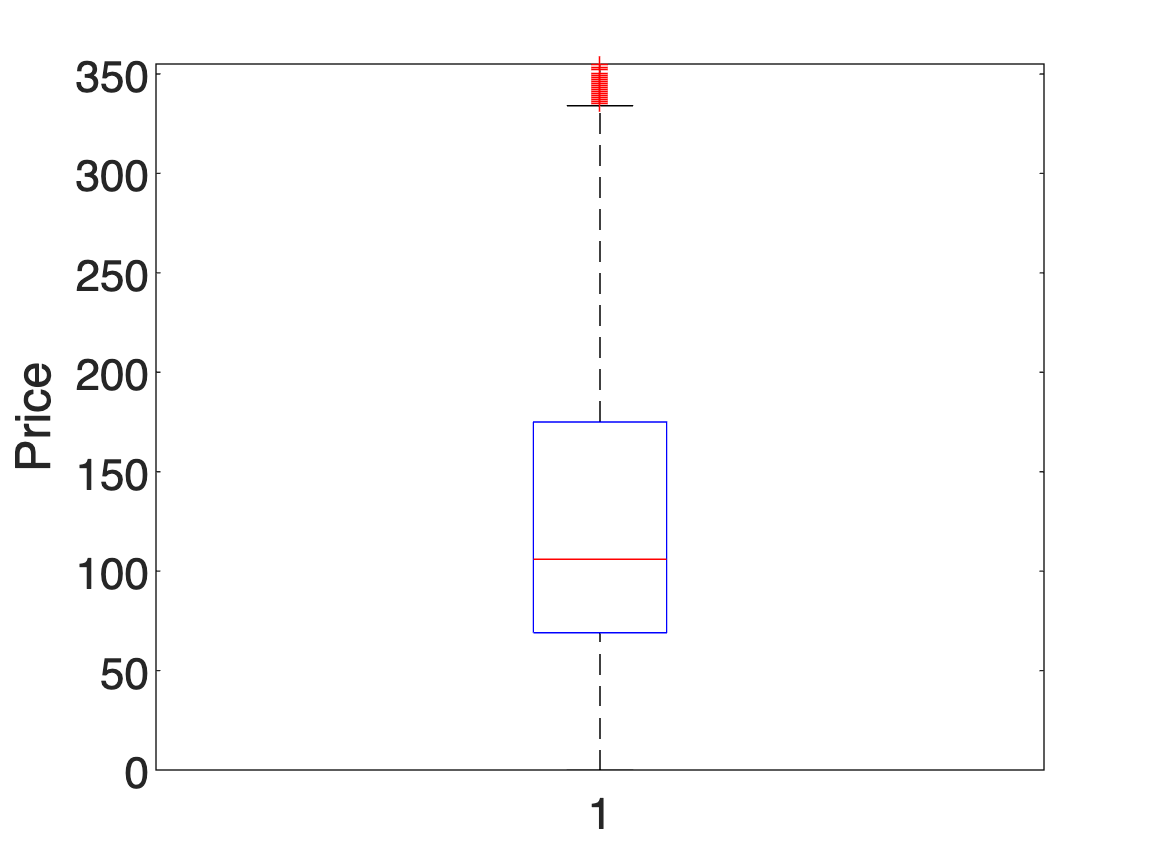

boxplot(price);
ylabel('Price')
ylim([0,prctile(price,95)])
set(gca, 'fontsize', 16);

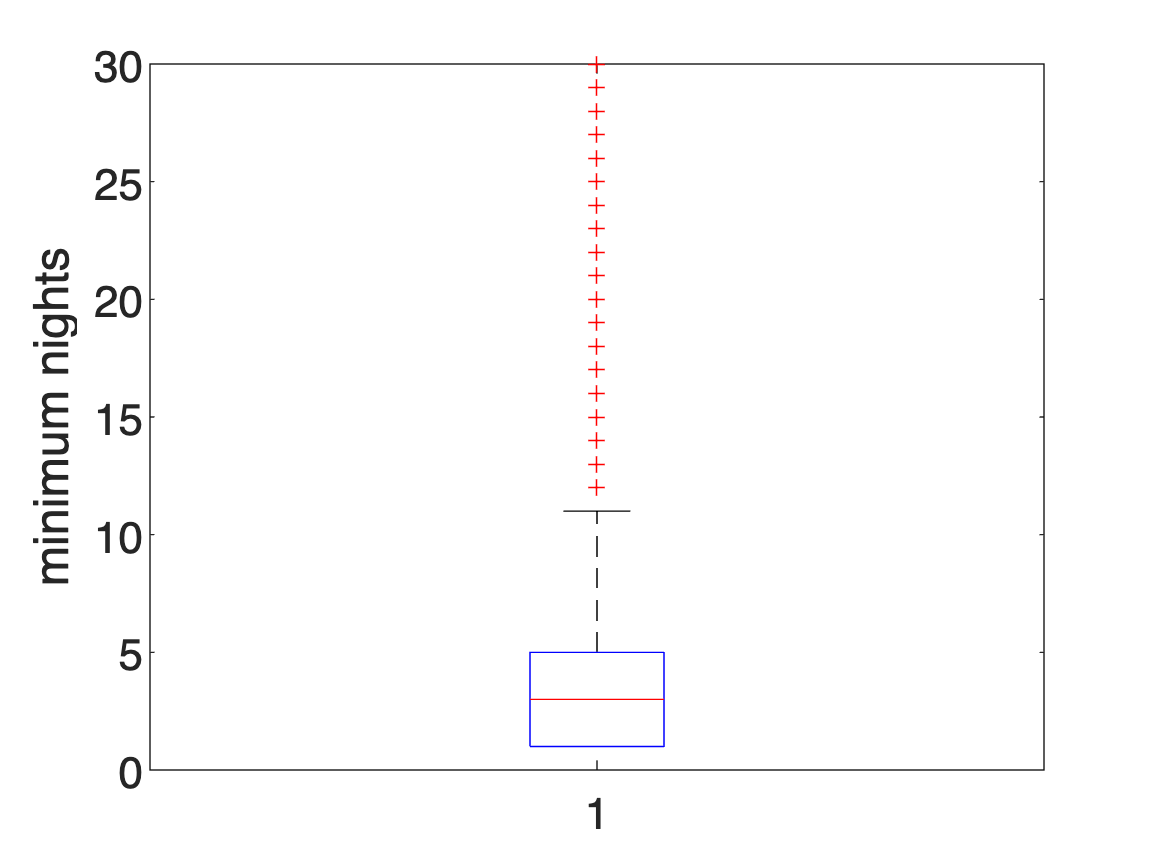

minimum_nights=data.minimum_nights;
boxplot(minimum_nights)
ylabel('minimum nights')
ylim([0,prctile(minimum_nights,95)])
set(gca, 'fontsize', 16); 

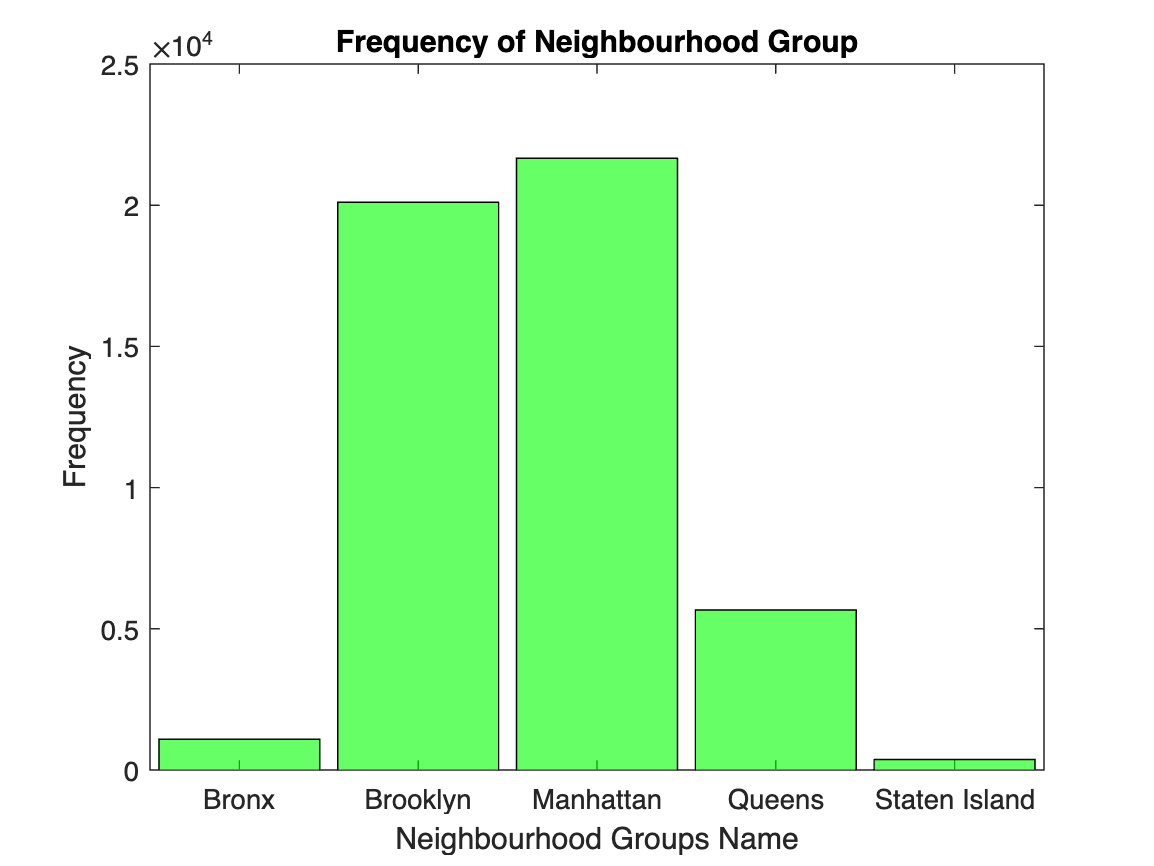


neighbourhood_group = categorical(table.neighbourhood_group);
histogram(neighbourhood_group,'FaceColor', 'green')
title('Frequency of Neighbourhood Group');
xlabel('Neighbourhood Groups Name');
ylabel('Frequency');

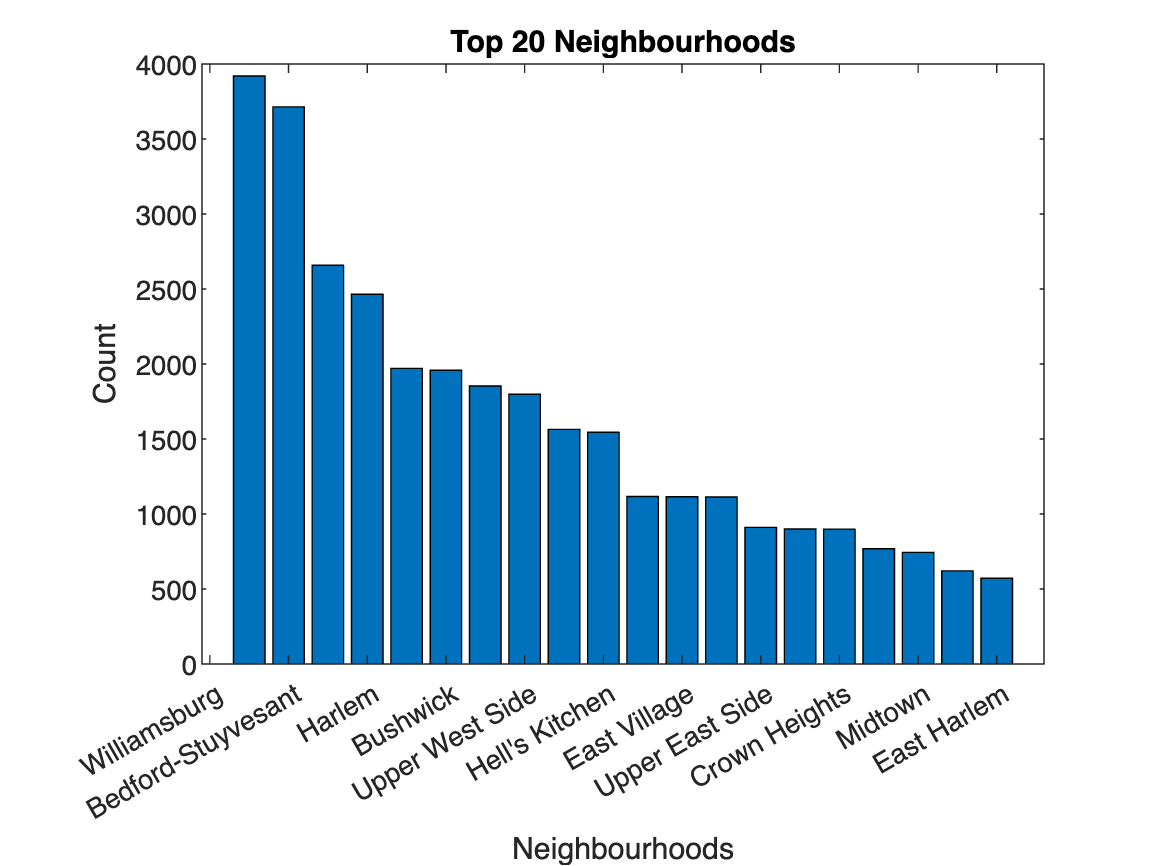

neighbourhood = categorical(table.neighbourhood);
[freq, cats] = histcounts(neighbourhood);
[sorted_freq, idx] = sort(freq, 'descend');
num_categories = 20;
bar(sorted_freq(1:num_categories));
xticklabels(cats(idx(1:num_categories)));
title('Top 20 Neighbourhoods');
xlabel('Neighbourhoods');
ylabel('Count');

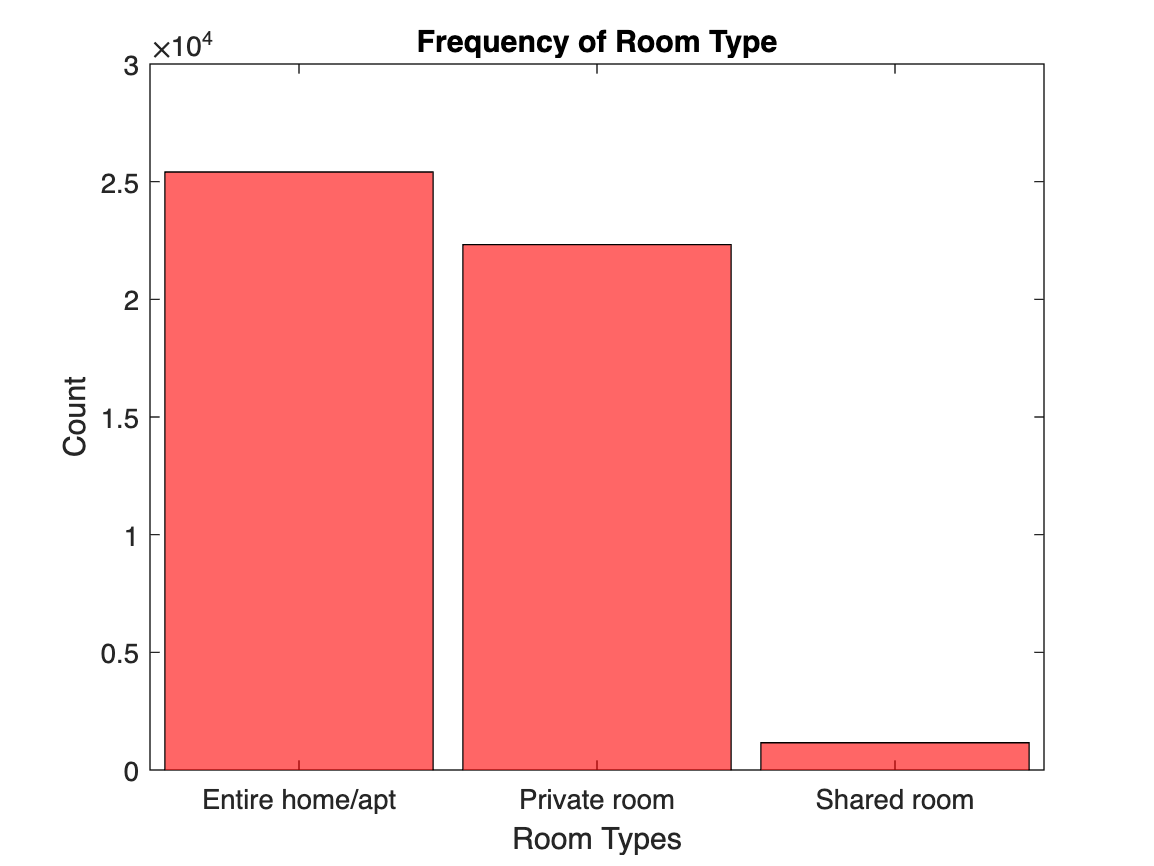

room_type = categorical(table.room_type);
histogram(room_type,'FaceColor', 'red')
title('Frequency of Room Type');
xlabel('Room Types');
ylabel('Count');

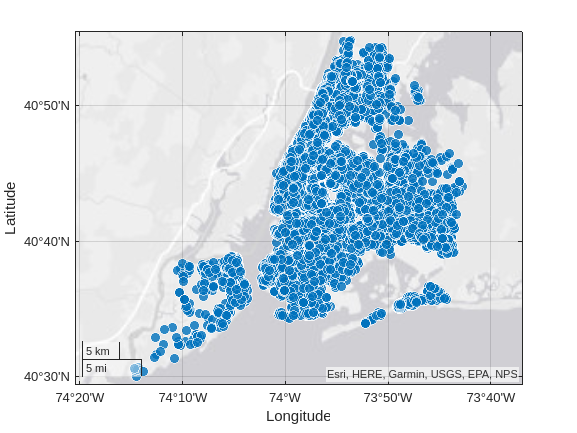

lat = table.latitude;
lon = table.longitude;
geobubble(lat, lon);

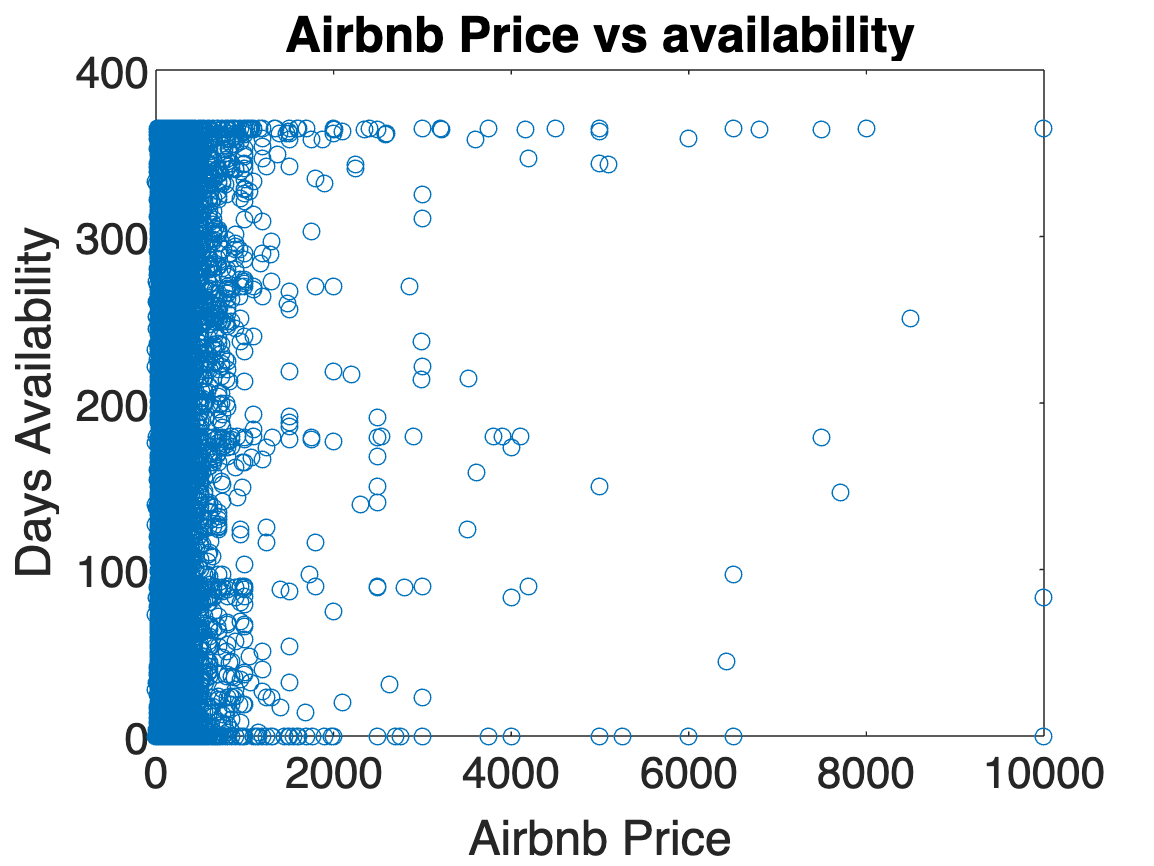

%Selected pairs of variables (both numerical, one numerical + one categorical)
price = table.price;
available = table.availability_365;
scatter(price,available)
xlabel('Airbnb Price')
ylabel('Days Availability')
set(gca, 'fontsize', 16)
title('Airbnb Price vs availability','fontsize', 18)
box on

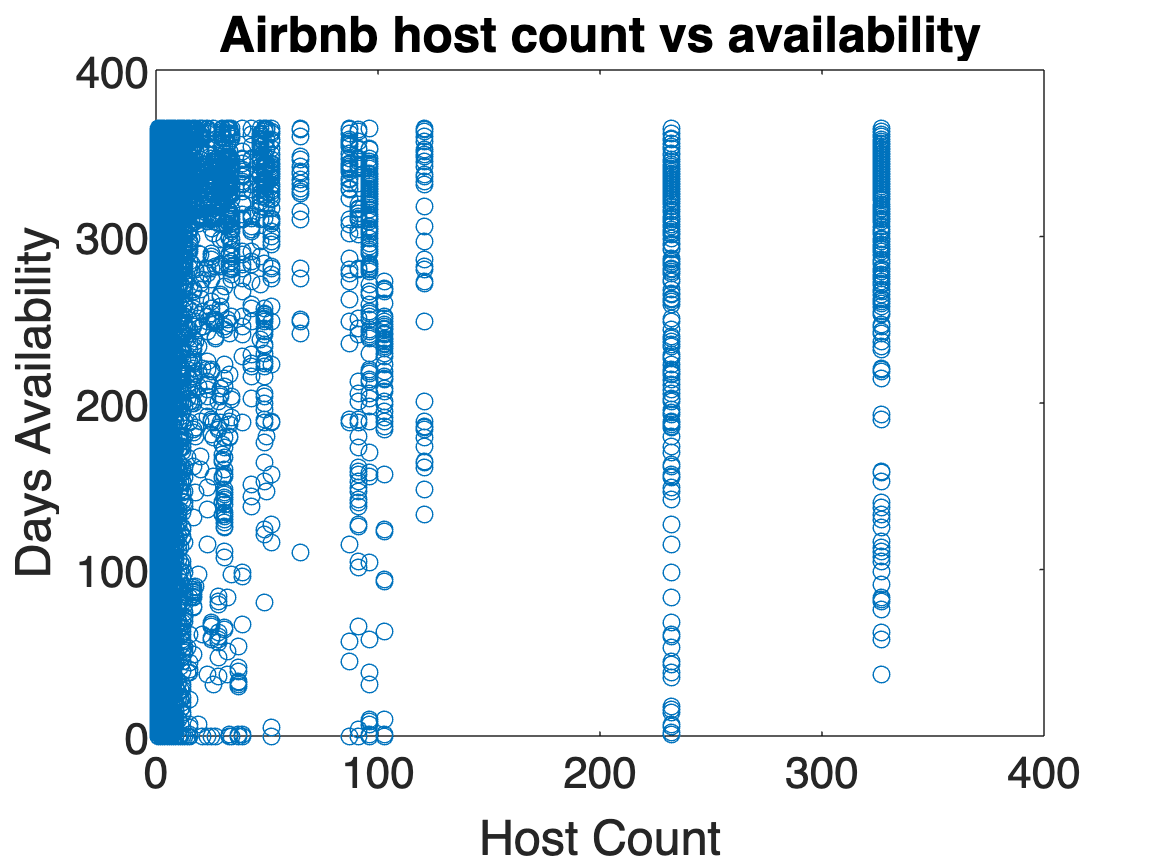

host_count = table.calculated_host_listings_count;
available = table.availability_365;
scatter(host_count,available)
xlabel('Host Count')
ylabel('Days Availability')
set(gca, 'fontsize', 16)
title('Airbnb host count vs availability','fontsize', 18)
box on

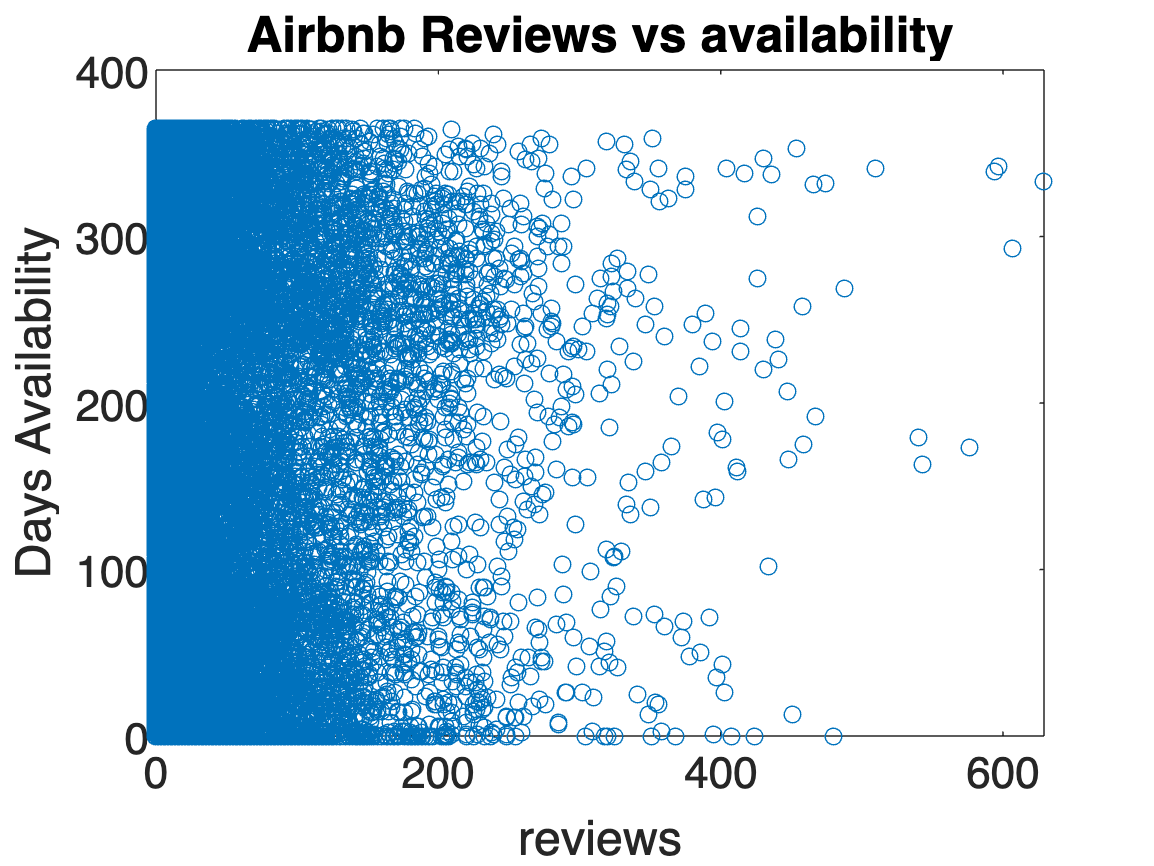

reviews = table.number_of_reviews;
available = table.availability_365;
scatter(reviews,available)
xlabel('reviews')
ylabel('Days Availability')
set(gca, 'fontsize', 16)
title('Airbnb Reviews vs availability','fontsize', 18)
box on

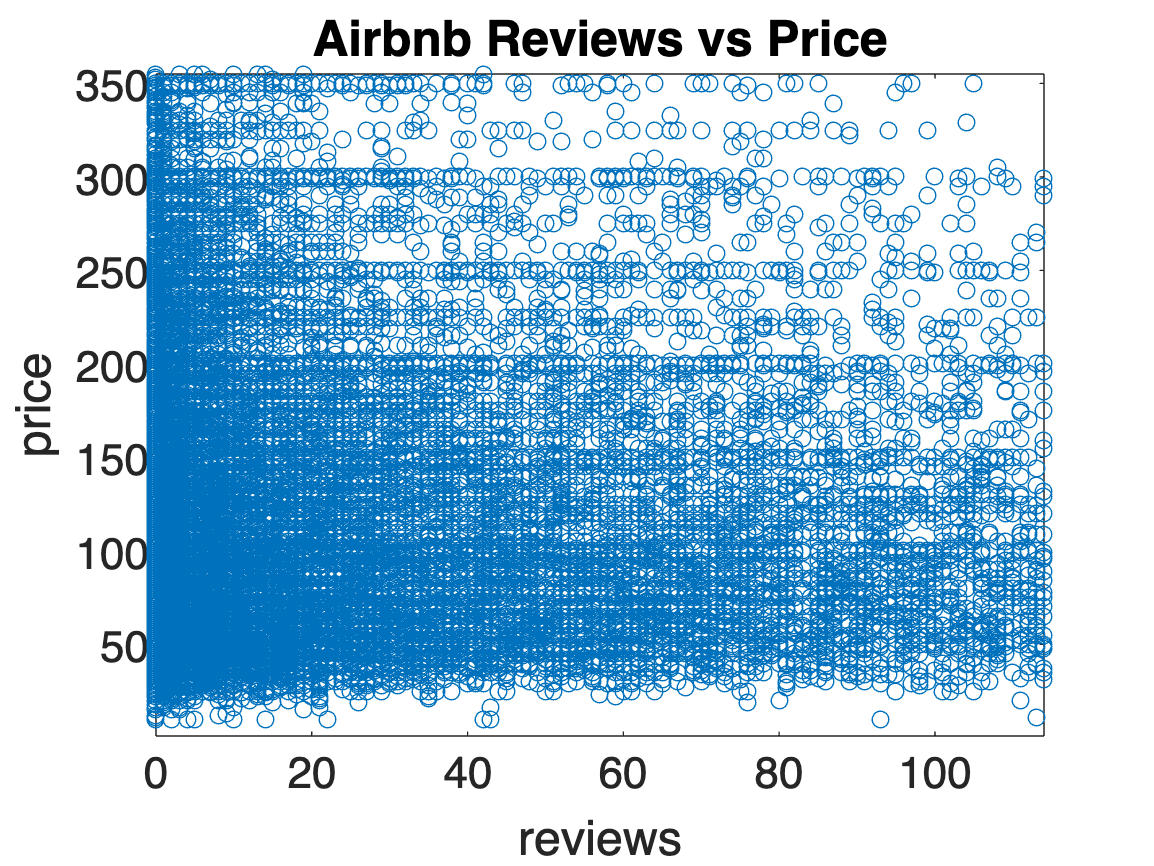

reviews = table.number_of_reviews;
price = table.price;
scatter(reviews,price)
ylim([1,prctile(price,95)])
xlim([0,prctile(reviews,95)])
xlabel('reviews')
ylabel('price')
set(gca, 'fontsize', 16)
title('Airbnb Reviews vs Price','fontsize', 18)
box on

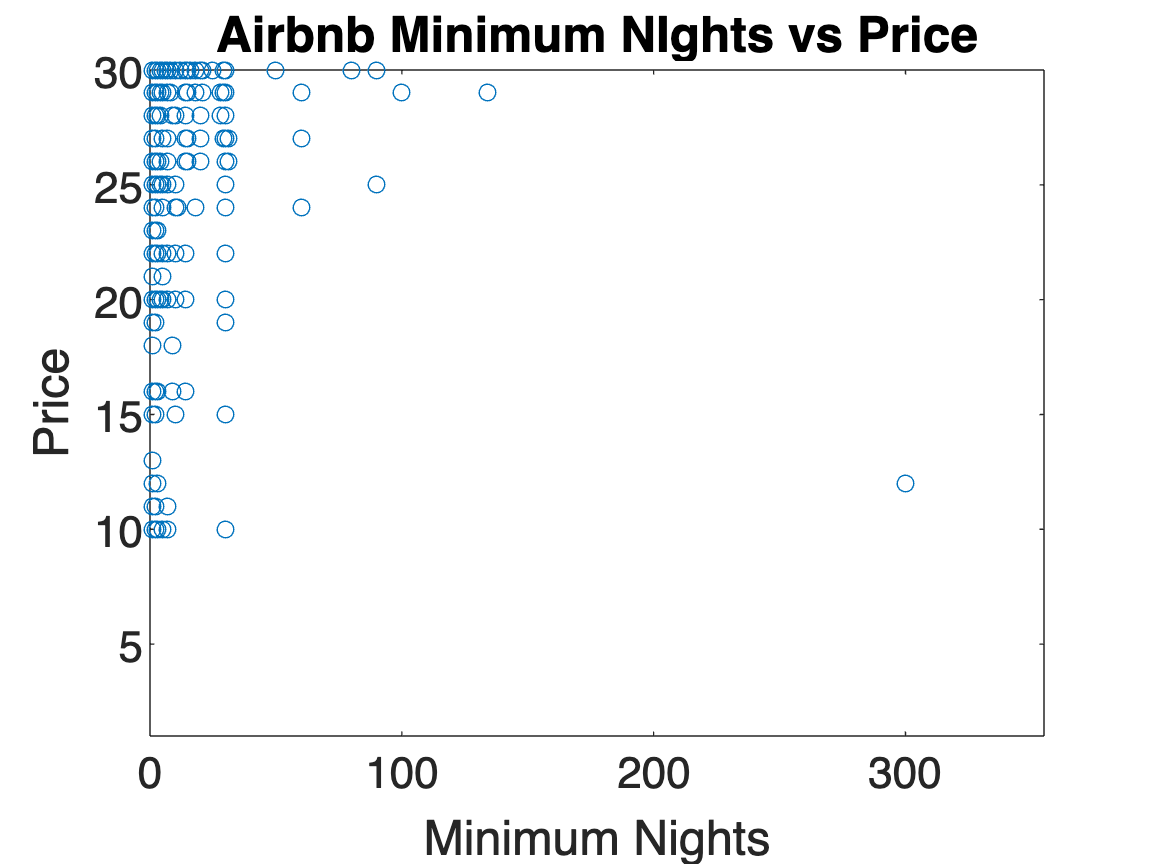

nights = table.minimum_nights;
price = table.price;
scatter(nights,price)
ylim([1,prctile(nights,95)])
xlim([0,prctile(price,95)])
xlabel('Minimum Nights')
ylabel('Price')
set(gca, 'fontsize', 16)
title('Airbnb Minimum NIghts vs Price','fontsize', 18)
box on

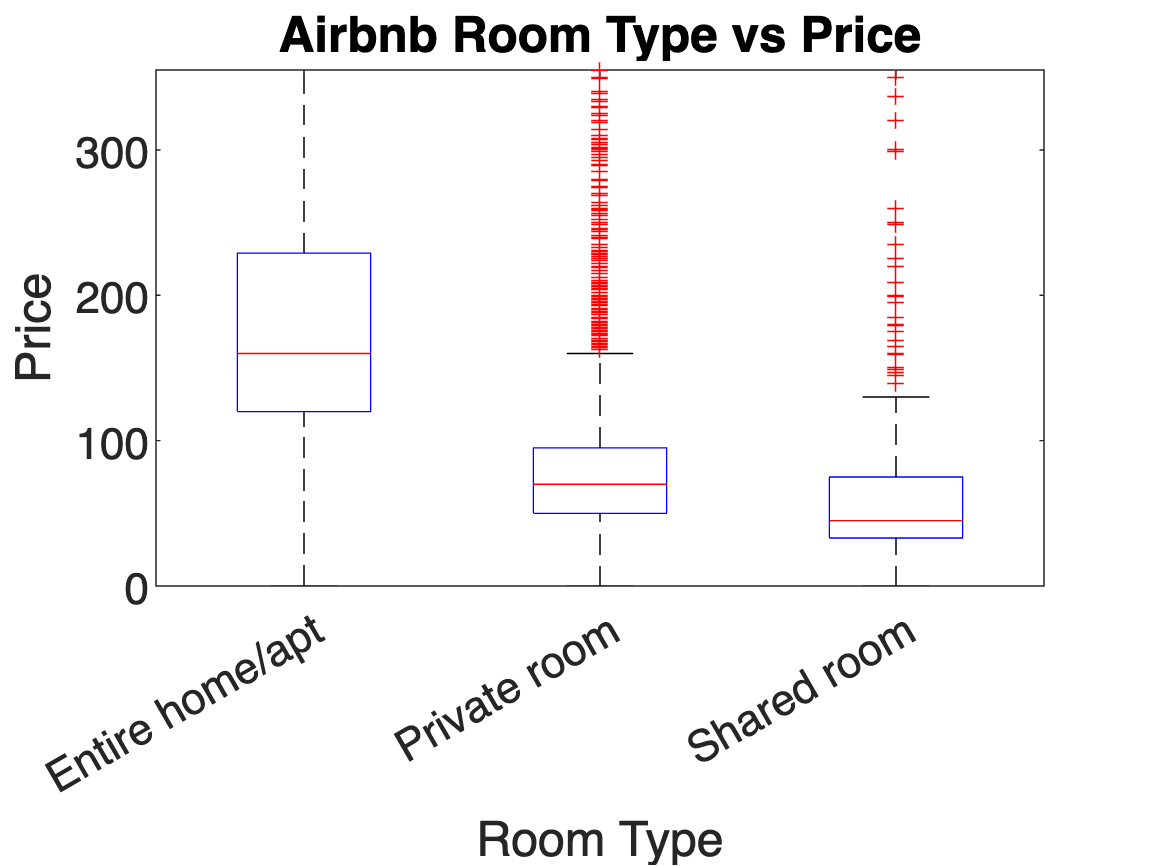

room_type = categorical(table.room_type);
price = table.price;
boxplot(price,room_type)
xlabel('Room Type')
ylabel('Price')
ylim([0,prctile(price,95)])
set(gca, 'fontsize', 16)
title('Airbnb Room Type vs Price','fontsize', 18)
box on

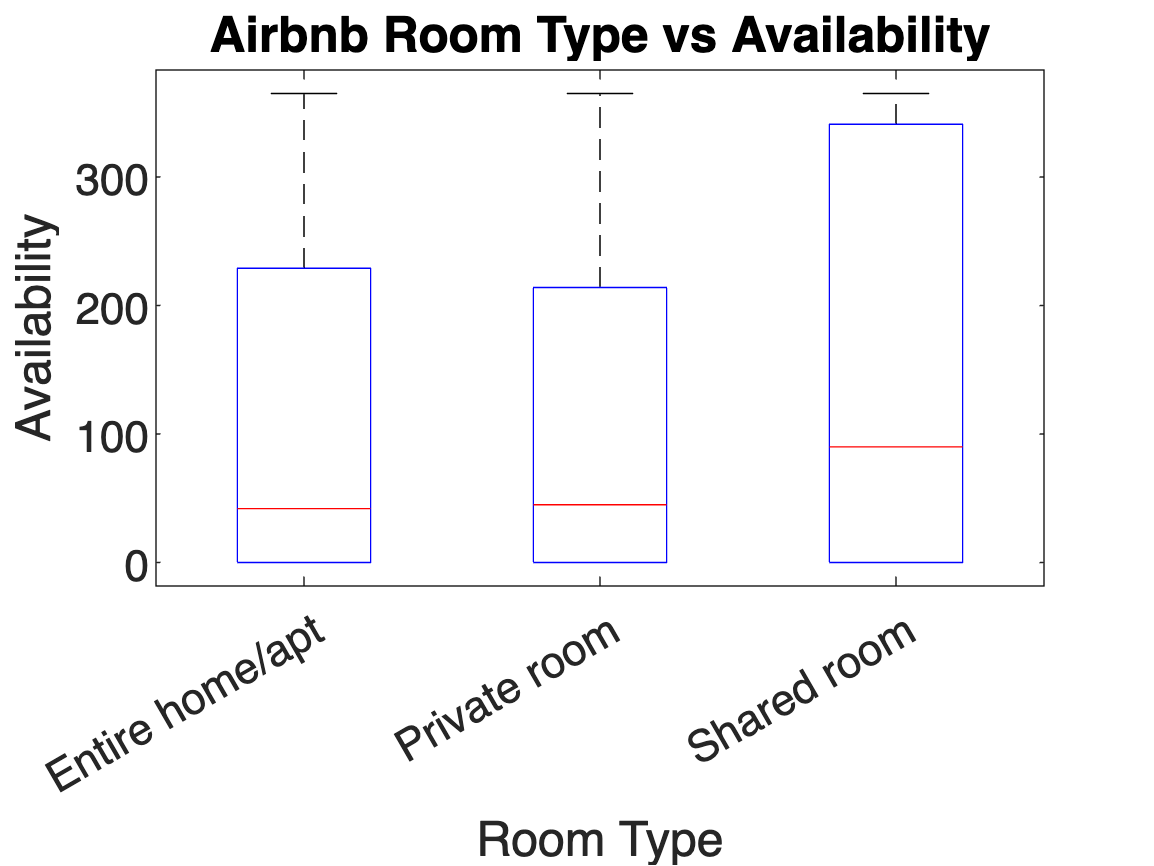

room_type = categorical(table.room_type);
available = table.availability_365;
boxplot(available,room_type)
xlabel('Room Type')
ylabel('Availability')
set(gca, 'fontsize', 16)
title('Airbnb Room Type vs Availability','fontsize', 18)
box on

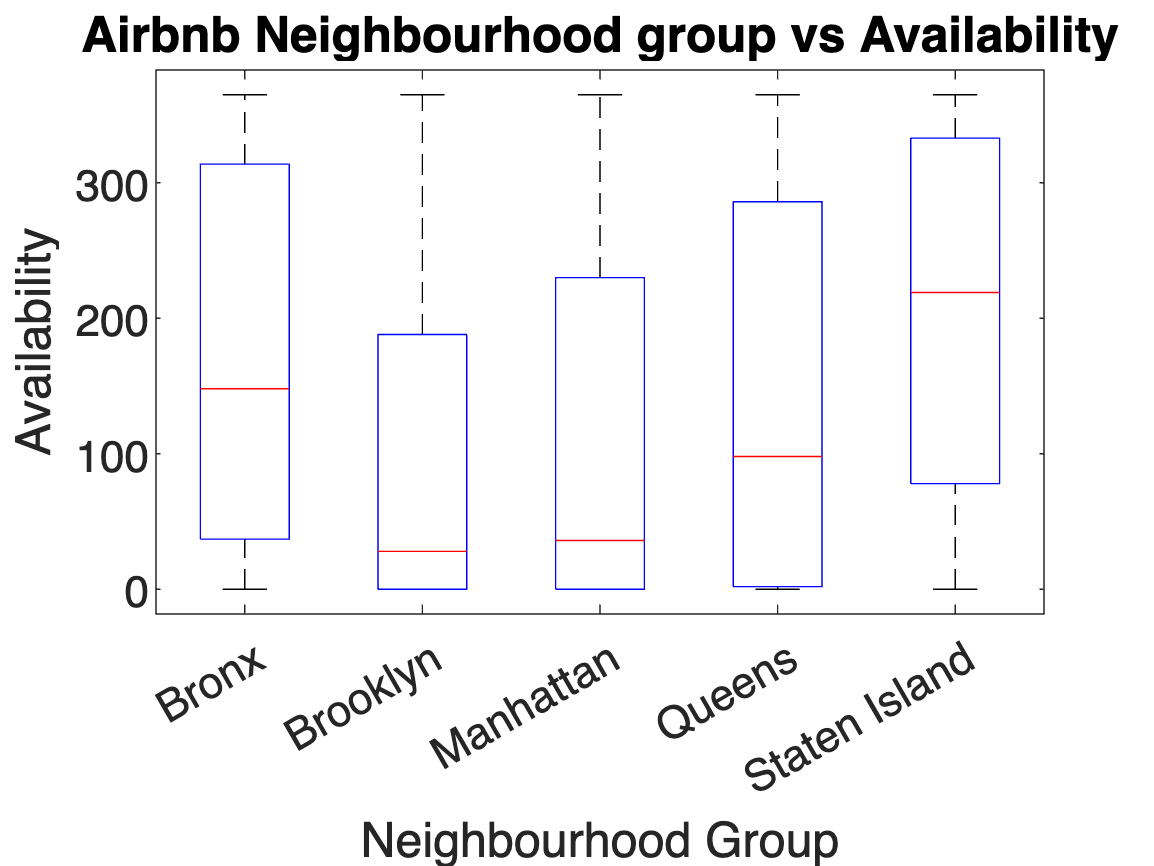

neigh_group = categorical(table.neighbourhood_group);
available = table.availability_365;
boxplot(available,neigh_group)
xlabel('Neighbourhood Group')
ylabel('Availability')
set(gca, 'fontsize', 16)
title('Airbnb Neighbourhood group vs Availability','fontsize', 18)
box on

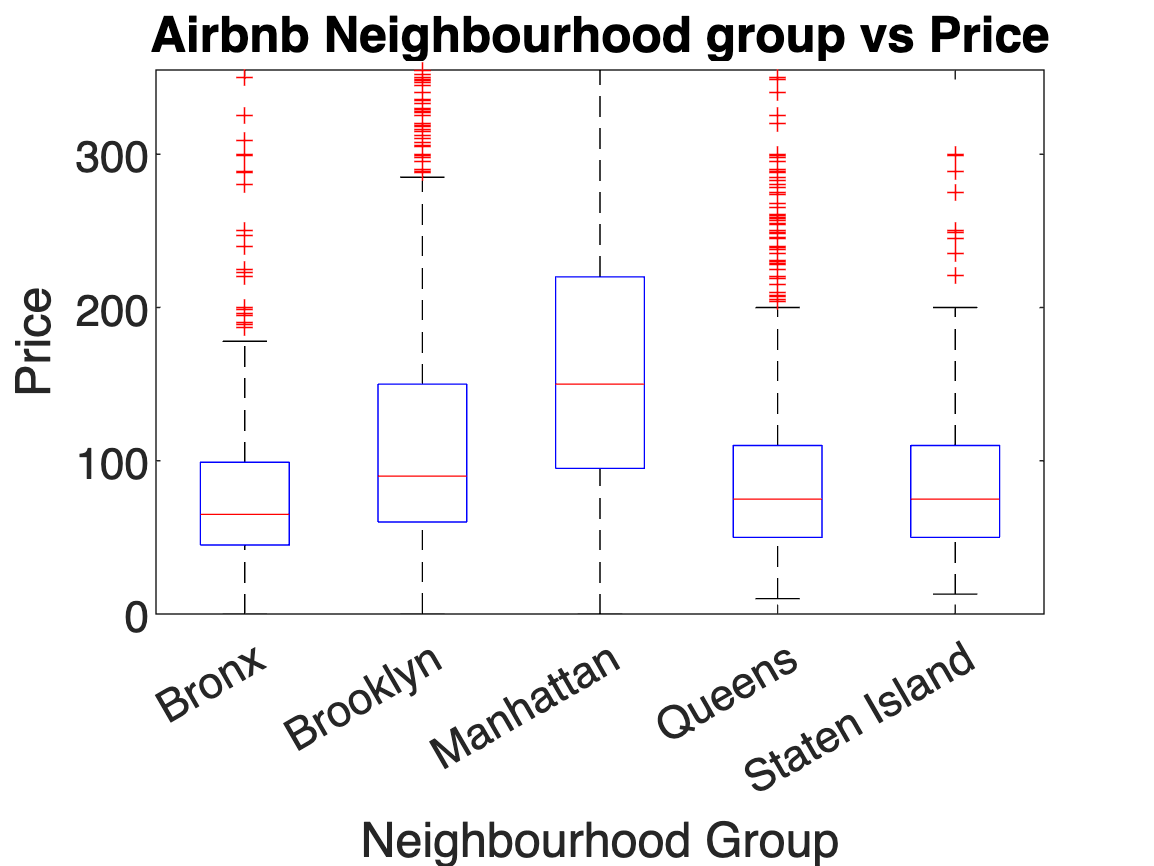

neigh_group = categorical(table.neighbourhood_group);
price = table.price;
boxplot(price,neigh_group)
ylim([0,prctile(price,95)])
xlabel('Neighbourhood Group')
ylabel('Price')
set(gca, 'fontsize', 16)
title('Airbnb Neighbourhood group vs Price','fontsize', 18)
box on

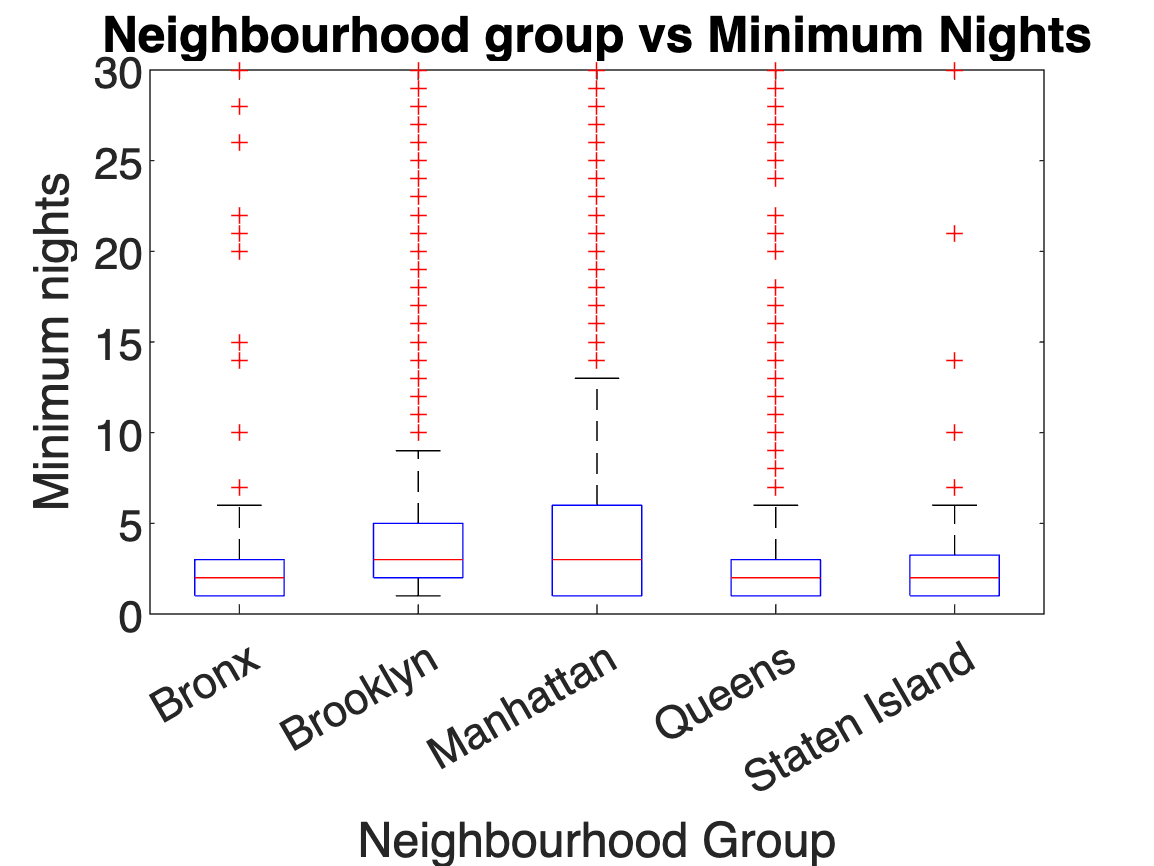

neigh_group = categorical(table.neighbourhood_group);
nights = table.minimum_nights;
boxplot(nights,neigh_group)
xlabel('Neighbourhood Group')
ylabel('Minimum nights')
ylim([0,prctile(nights,95)])
set(gca, 'fontsize', 16)
title('Neighbourhood group vs Minimum Nights','fontsize', 18)
box on

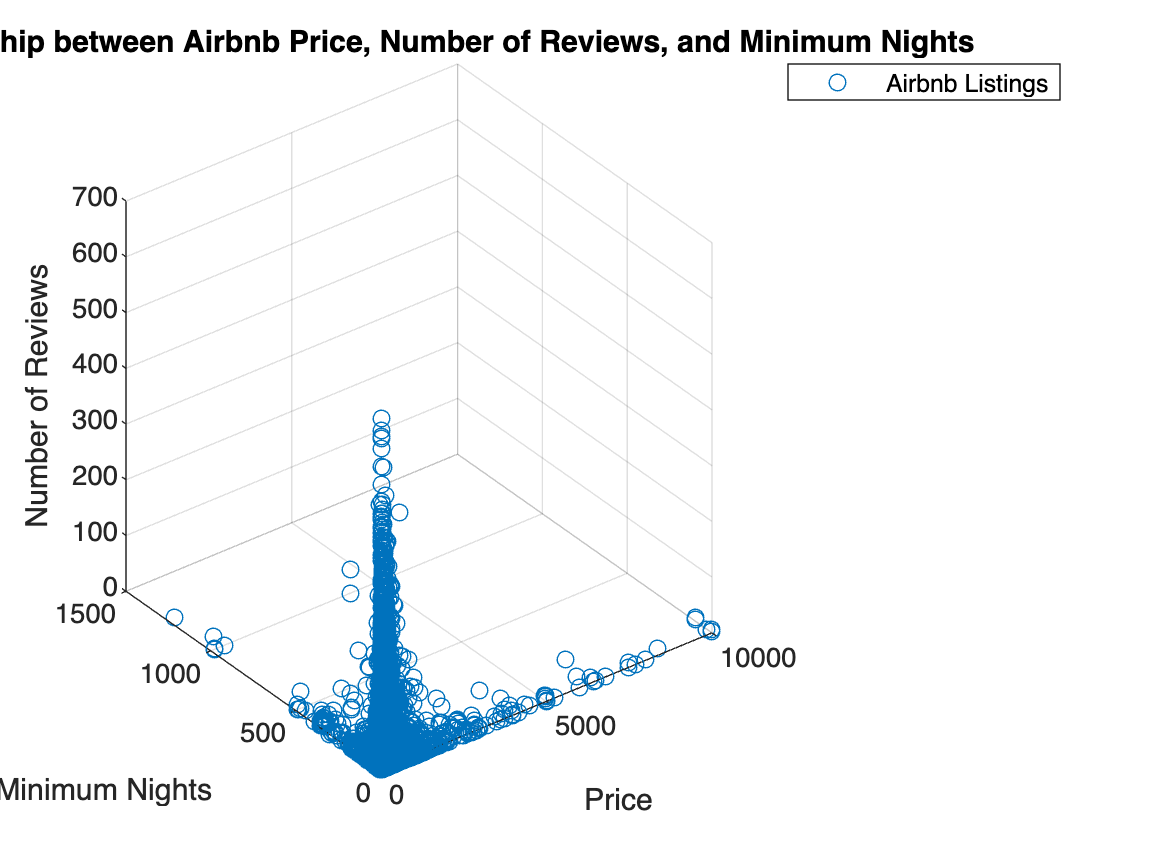

number_of_reviews=data.number_of_reviews;
neighbourhood_group=data.neighbourhood_group;
room_type=data(:,9);
scatter3(price,minimum_nights, number_of_reviews);
xlabel('Price');
zlabel('Number of Reviews');
ylabel('Minimum Nights');
title('Relationship between Airbnb Price, Number of Reviews, and Minimum Nights');
legend('Airbnb Listings');

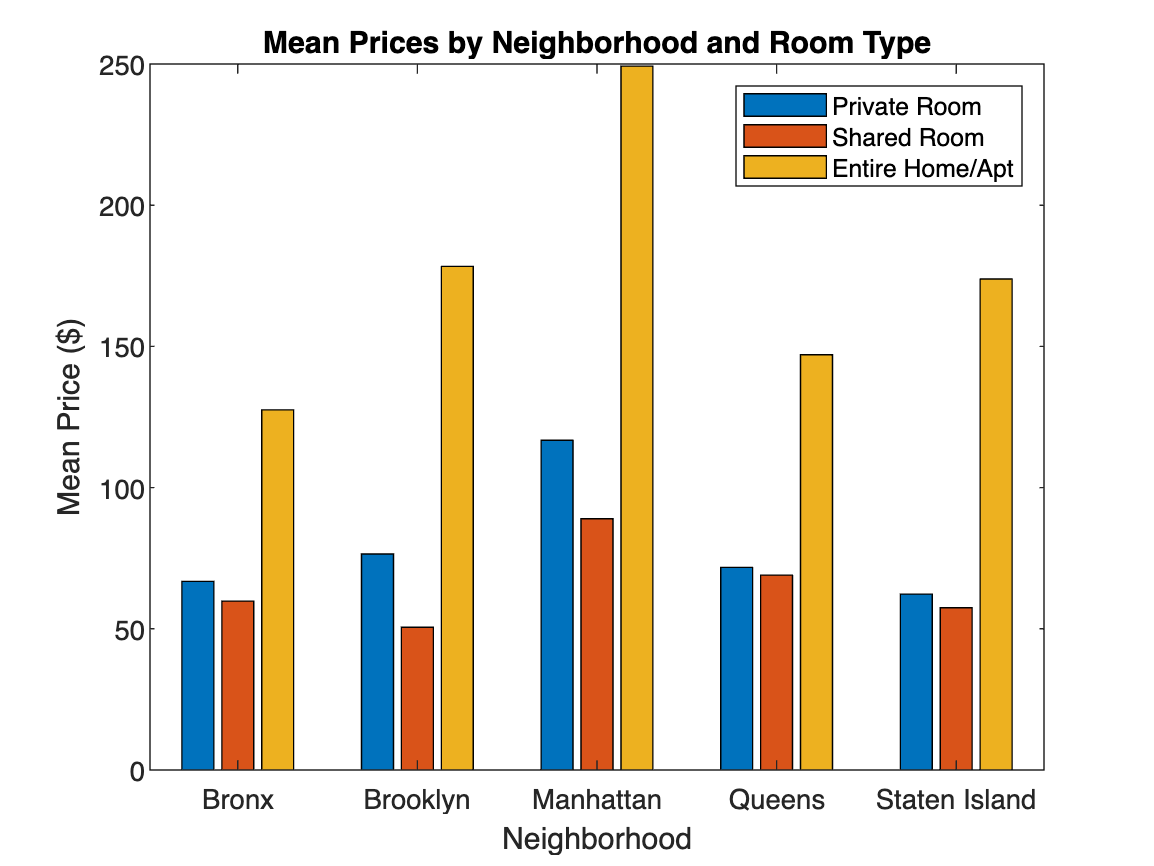


grouped_data = groupsummary(data,{'neighbourhood_group', 'room_type'},'mean','price');

xlabels = unique(grouped_data.neighbourhood_group);
ydata_private = grouped_data.mean_price(strcmp(grouped_data.room_type,'Private room'));
ydata_shared = grouped_data.mean_price(strcmp(grouped_data.room_type,'Shared room'));
ydata_entire = grouped_data.mean_price(strcmp(grouped_data.room_type,'Entire home/apt'));

% Create the bar chart
figure;
bar([ydata_private, ydata_shared, ydata_entire]);
set(gca,'XTickLabel',xlabels);
legend('Private Room', 'Shared Room', 'Entire Home/Apt');
ylabel('Mean Price ($)');
xlabel('Neighborhood');
title('Mean Prices by Neighborhood and Room Type');

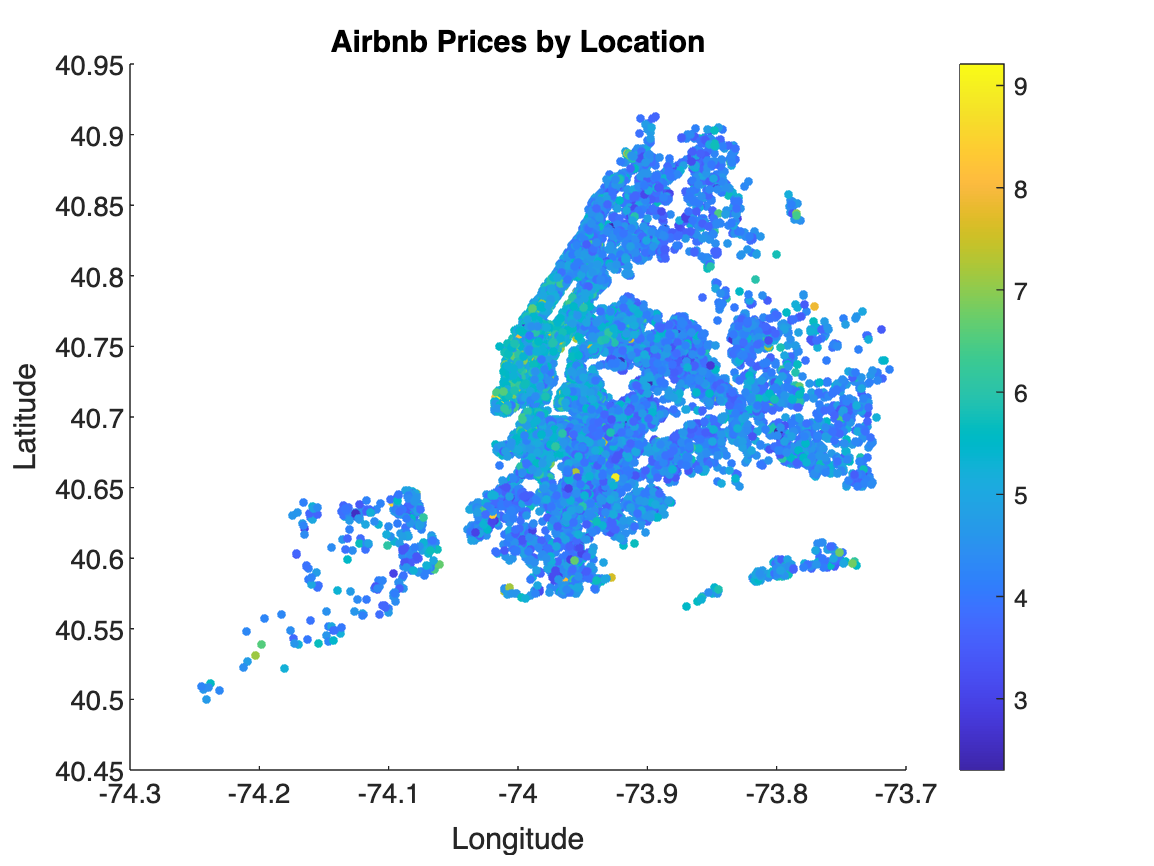

latitudes = data.latitude;
longitudes = data.longitude;
prices = data.price;


figure;
scatter(longitudes, latitudes, 10, log(prices), 'filled');
colormap(parula);
colorbar;
xlabel('Longitude');
ylabel('Latitude');
title('Airbnb Prices by Location');


missingValues = ismissing(table);
totalMissing = sum(missingValues(:));
totalValues = numel(table);
missingPercentage = (totalMissing / totalValues) * 100;
fprintf('Missing percentage: %.2f%%\n', missingPercentage);

Missing percentage: 2.57%



data = rmmissing(data)

data = 38821×16 table
     id                             name                            host_id        host_name        neighbourhood_group        neighbourhood         latitude    longitude         room_type         price    minimum_nights    number_of_reviews    last_review    reviews_per_month    calculated_host_listings_count    availability_365
    ____    ____________________________________________________    _______    _________________    ___________________    ______________________    ________    _________    ___________________    _____  

PRINCIPLE COMPONENT ANALYSIS

X = [data.price,data.minimum_nights,data.number_of_reviews,data.reviews_per_month,data.calculated_host_listings_count,data.availability_365];
norm_X = normalize(X)

norm_X =     0.0338   -0.2800   -0.4211   -0.6923    0.0317    1.9309
    0.4196   -0.2800    0.3260   -0.5911   -0.1204    1.8537
   -0.2707   -0.2800    4.9958    1.9441   -0.1584    0.6108
   -0.3164    0.2376   -0.4211   -0.7577   -0.1584   -0.8869
    0.2927   -0.1650    0.9279   -0.4661   -0.1584    0.1090
   -0.4179    2.2503    0.4091   -0.5792   -0.1584   -0.8869
   -0.3215   -0.2225    8.3164    1.2478   -0.1584    0.8115
   -0.3215   -0.2225    1.8411   -0.2281   -0.1584   -0.8869
    0.0389   -0.2800    2.7128   -0.0257   -0.0444    0.5645
   -0.0372   -0.0500    0.4921   -0.5613   -0.1584   -0.8406


xbar = mean(norm_X,1);
Xtilda = norm_X - xbar;

[U,S,V] = svds(Xtilda);

Y = U .* diag(S)';
V(:,1)

ans =    -0.0284
   -0.1336
    0.6534
    0.6573
    0.0110
    0.3497


(var(S) / sum(var(S))) * 100

ans =    27.8542   21.1458   16.2797   15.3112   11.9999    7.4092


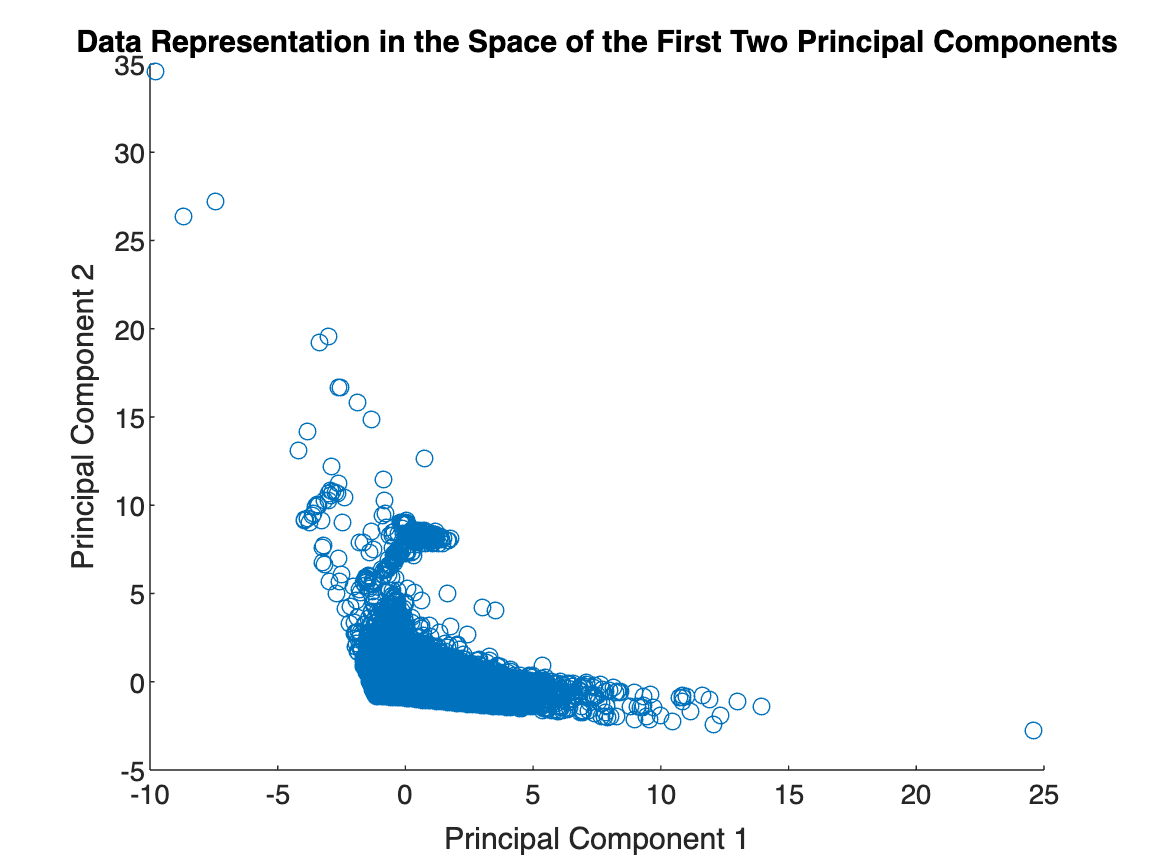


scatter(Y(:, 1), Y(:, 2));
xlabel('Principal Component 1');
ylabel('Principal Component 2');

title('Data Representation in the Space of the First Two Principal Components');

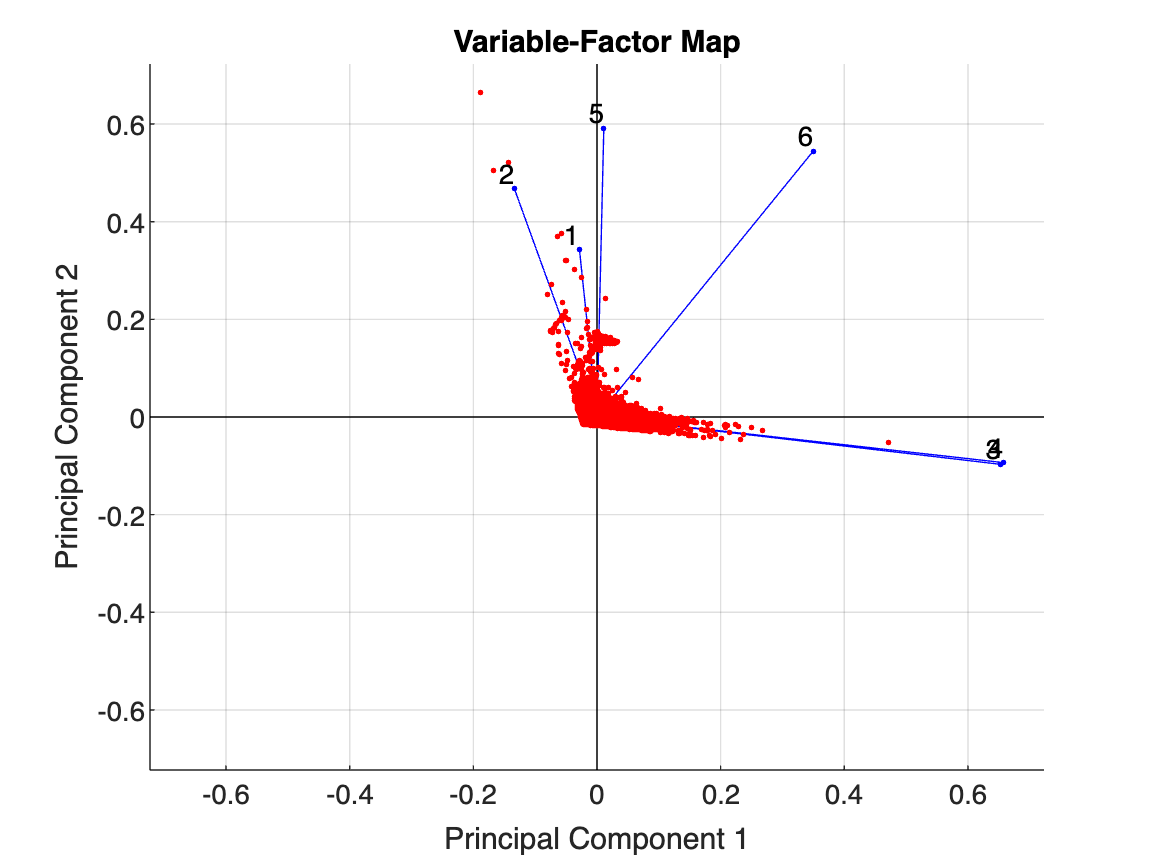

figure;
biplot(V(:,1:2), 'Scores', Y(:,1:2));
xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('Variable-Factor Map');

% Add labels to the variables
varLabels = cellstr(num2str((1:size(norm_X,2))'));
text(V(:,1), V(:,2), varLabels, 'VerticalAlignment','bottom', 'HorizontalAlignment','right');

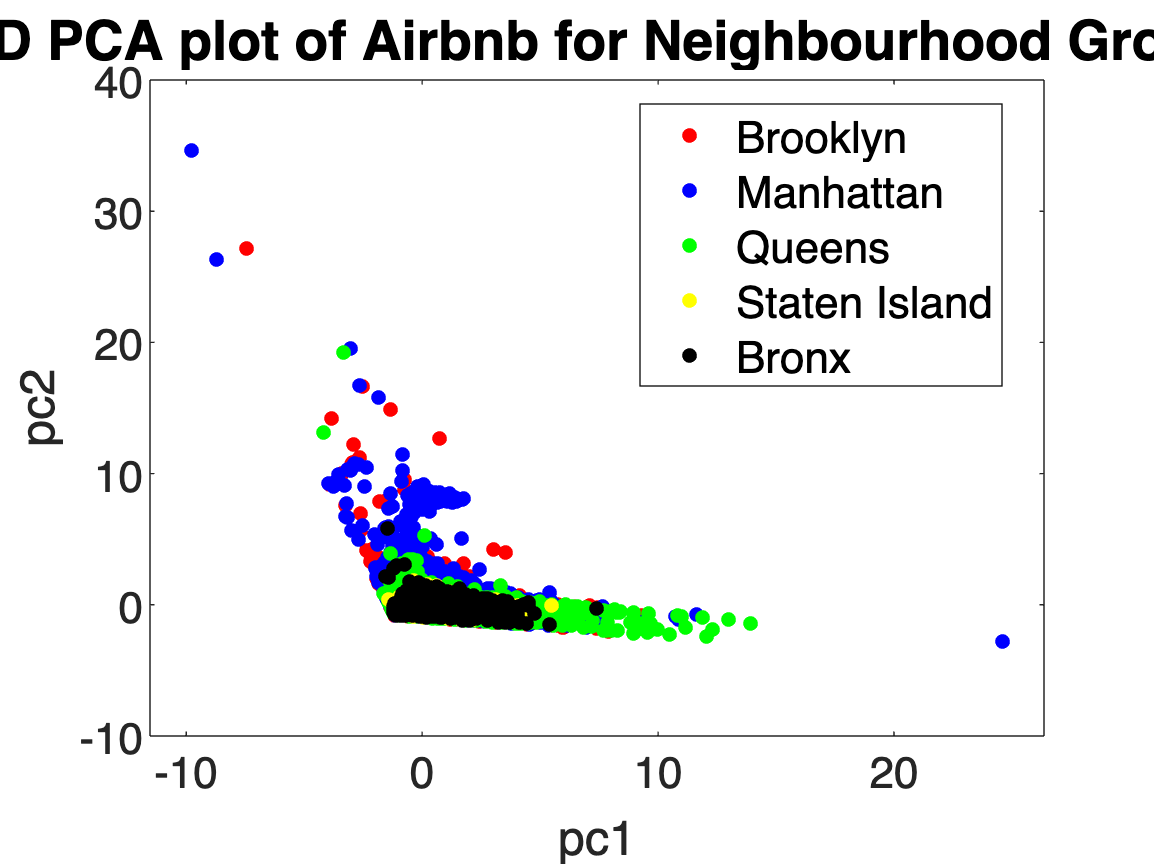

figure; 
gscatter(Y(:,1), Y(:,2), data.neighbourhood_group, 'rbgyk', '...', 16)
set(gca, 'fontsize', 16)
xlabel('pc1')
ylabel('pc2')
title('2D PCA plot of Airbnb for Neighbourhood Group', 'fontsize', 20)
legend('fontsize', 16)
box on

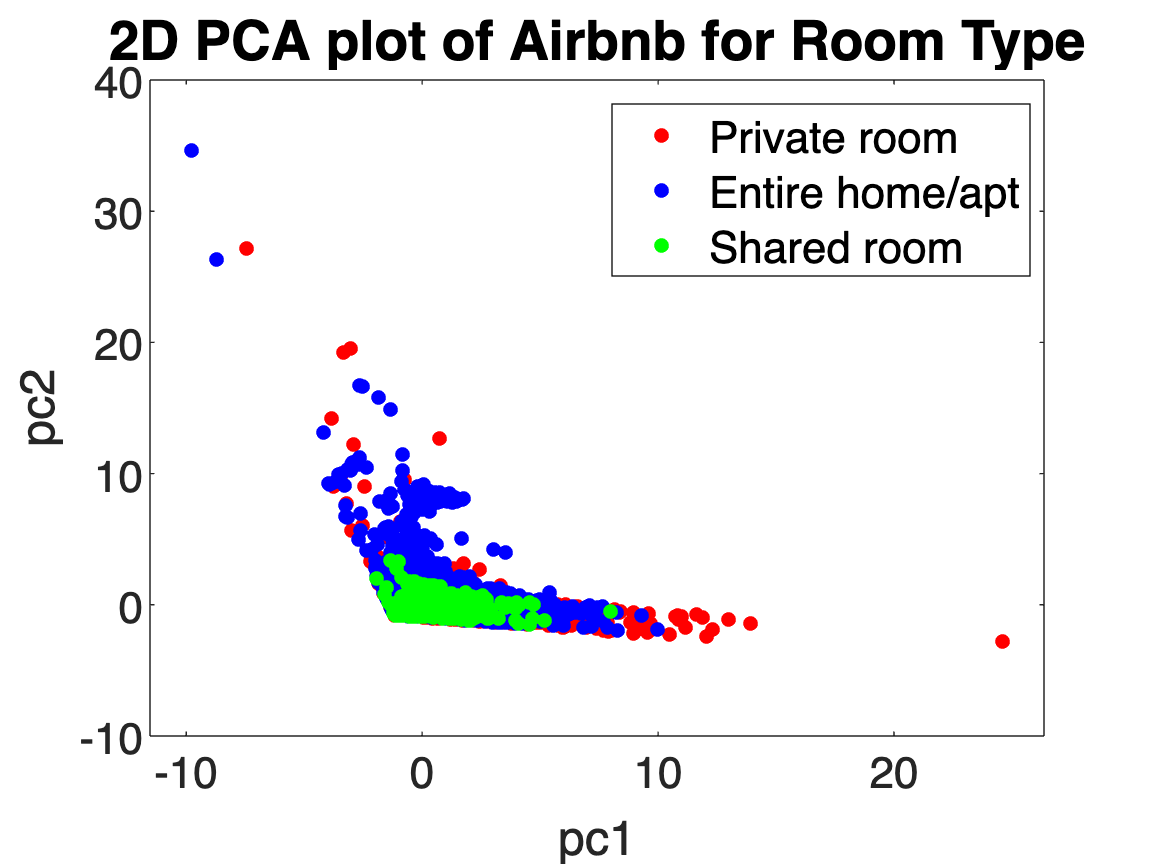

figure; 
gscatter(Y(:,1), Y(:,2), data.room_type, 'rbg', '...', 16)
set(gca, 'fontsize', 16)
xlabel('pc1')
ylabel('pc2')
title('2D PCA plot of Airbnb for Room Type', 'fontsize', 20)
legend('fontsize', 16)
box on

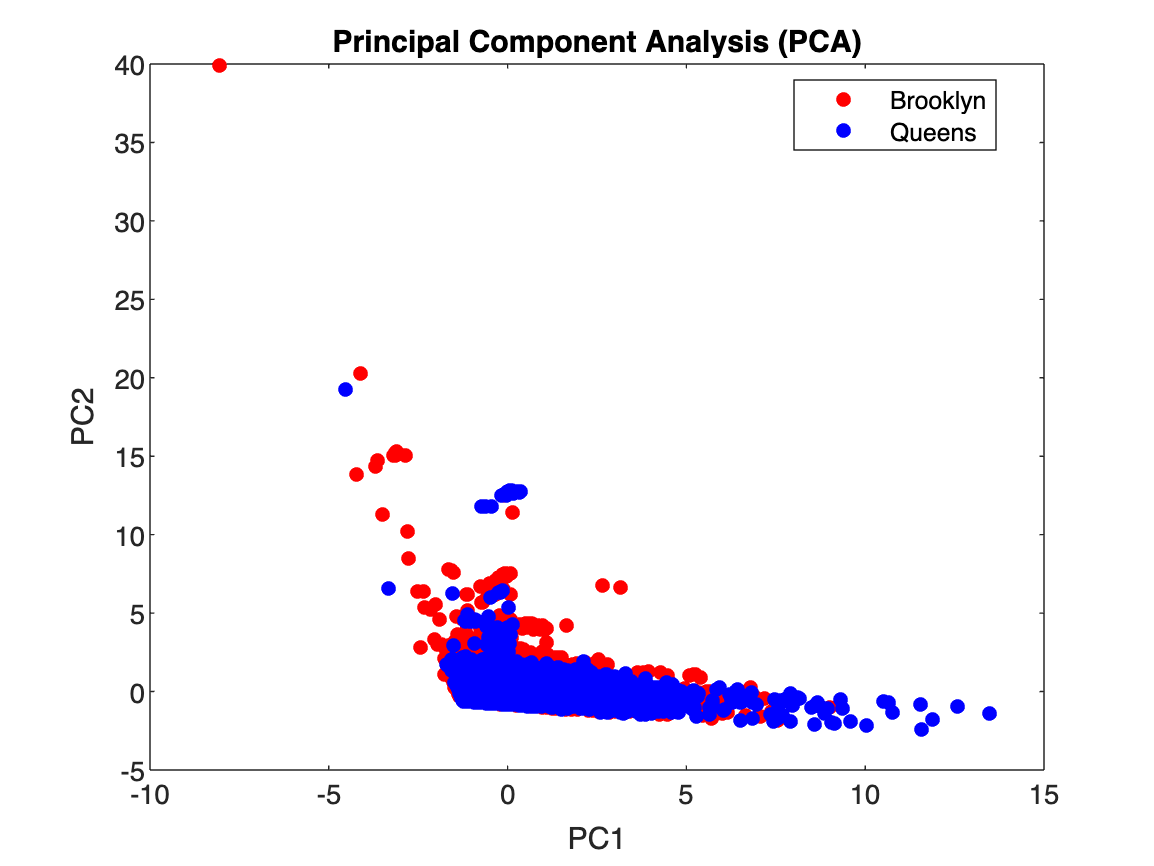

neighbourGroups = {'Queens', 'Brooklyn'};
filter = ismember(data.neighbourhood_group, neighbourGroups);
filteredData = data(filter, :);
% Extract the numerical variables from the filtered data into variable X
X1 = [filteredData.price, filteredData.minimum_nights, filteredData.number_of_reviews, ...
      filteredData.reviews_per_month, filteredData.calculated_host_listings_count, ...
      filteredData.availability_365];

norm_X1 = normalize(X1);
xbar = mean(norm_X1, 1);
Xtilda = norm_X1 - xbar;

% Perform singular value decomposition (SVD)
[U, S] = svd(Xtilda,'econ');
Yp = U .* diag(S)';

% Calculate the explained variance percentage of the first PCA
explained_var = (var(S) / sum(var(S))) * 100;
explained_var_pca1 = explained_var(1);

% Plot the two principal components for the neighborhood groups
gscatter(Yp(:, 1), Yp(:, 2), filteredData.neighbourhood_group,'rb', '..', 16);
xlabel('PC1');
ylabel('PC2');
title('Principal Component Analysis (PCA)');

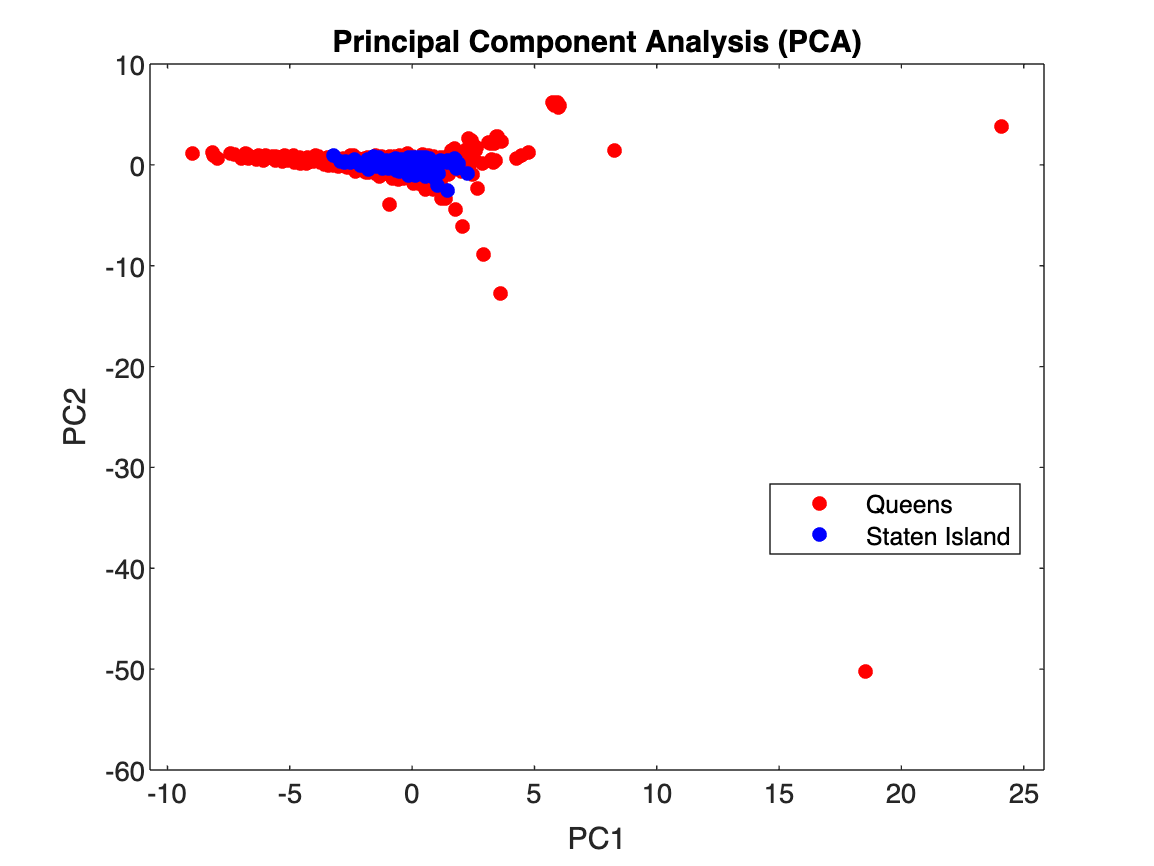

neighbourGroups2 = {'Queens', 'Staten Island'};
filter = ismember(data.neighbourhood_group, neighbourGroups2);
filteredData = data(filter, :);
% Extract the numerical variables from the filtered data into variable X
X2 = [filteredData.price, filteredData.minimum_nights, filteredData.number_of_reviews, ...
      filteredData.reviews_per_month, filteredData.calculated_host_listings_count, ...
      filteredData.availability_365];

norm_X2 = normalize(X2);
xbar = mean(norm_X2, 2);
Xtilda2 = norm_X2 - xbar;

% Perform singular value decomposition (SVD)
[U, S] = svd(Xtilda2,'econ');
Yp = U .* diag(S)';

% Calculate the explained variance percentage of the first PCA
explained_var = (var(S) / sum(var(S))) * 100;
explained_var_pca1 = explained_var(1);

% Plot the two principal components for the neighborhood groups
gscatter(Yp(:, 1), Yp(:, 2), filteredData.neighbourhood_group,'rb', '..', 16);
xlabel('PC1');
ylabel('PC2');
title('Principal Component Analysis (PCA)');

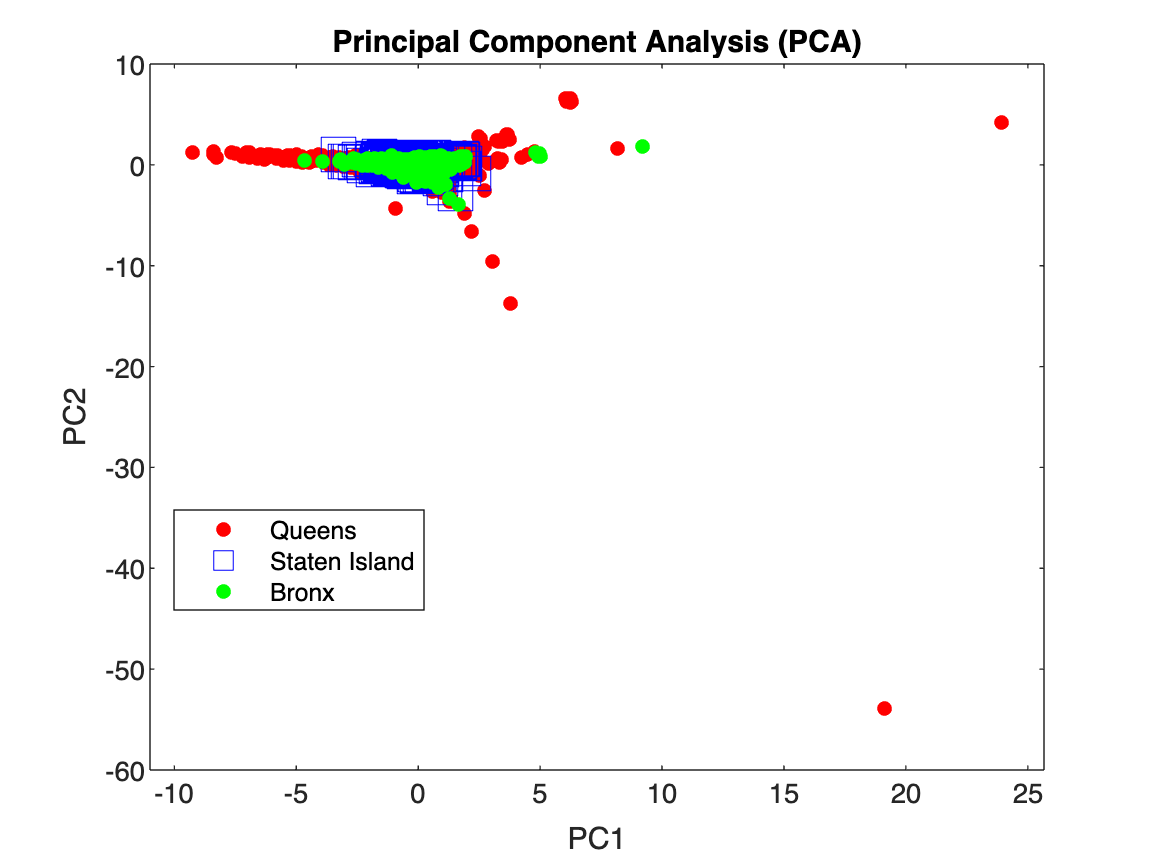

neighbourGroups3 = {'Queens', 'Staten Island','Bronx'};
filter = ismember(data.neighbourhood_group, neighbourGroups3);
filteredData = data(filter, :);
% Extract the numerical variables from the filtered data into variable X
X3 = [filteredData.price, filteredData.minimum_nights, filteredData.number_of_reviews, ...
      filteredData.reviews_per_month, filteredData.calculated_host_listings_count, ...
      filteredData.availability_365];

norm_X3 = normalize(X3);
xbar = mean(norm_X3, 2);
Xtilda3 = norm_X3 - xbar;

% Perform singular value decomposition (SVD)
[U, S] = svd(Xtilda3,'econ');
Yp = U .* diag(S)';

% Calculate the explained variance percentage of the first PCA
explained_var = (var(S) / sum(var(S))) * 100;
explained_var_pca1 = explained_var(1);

% Plot the two principal components for the neighborhood groups
gscatter(Yp(:, 1), Yp(:, 2), filteredData.neighbourhood_group,'rbg', '.s.', 16);
xlabel('PC1');
ylabel('PC2');
title('Principal Component Analysis (PCA)');

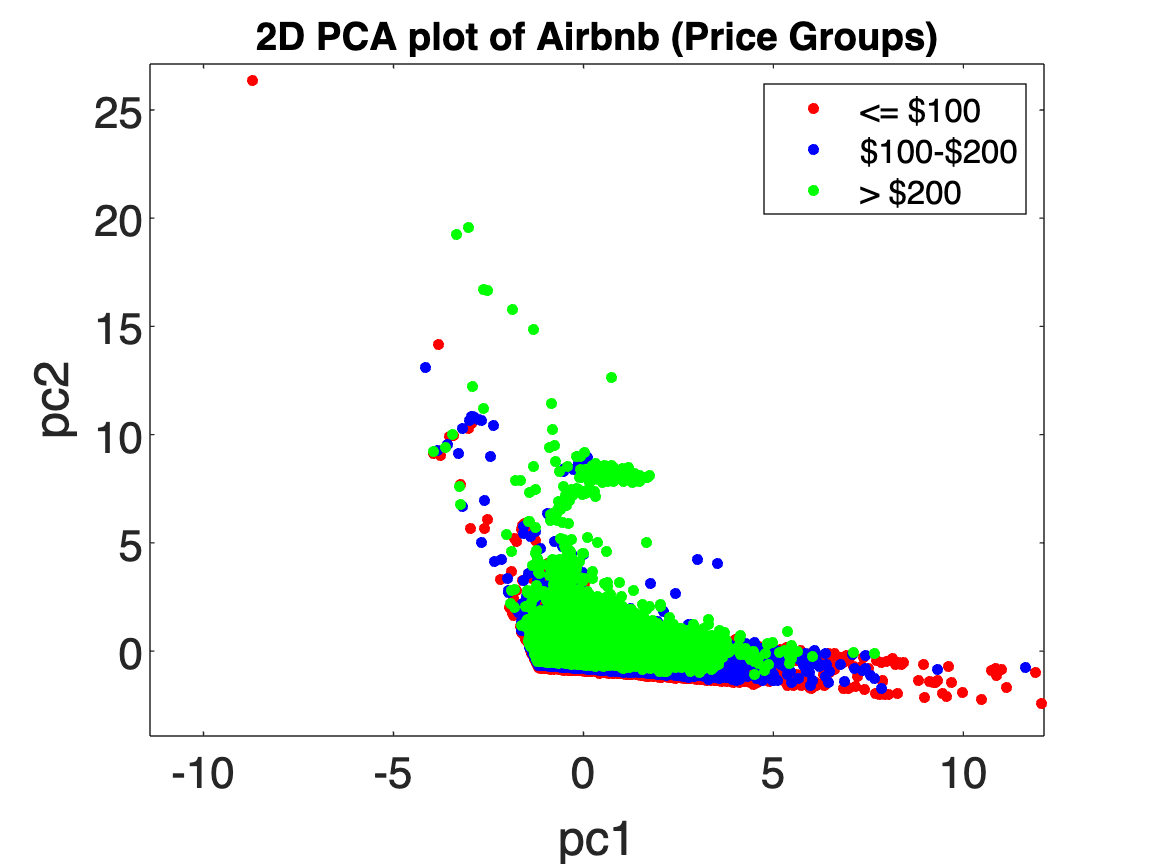

%LDA

price_groups = discretize(data.price, [0 100 200 max(data.price)+1]);

figure;
gscatter(Y(:,1), Y(:,2), price_groups, 'rbg', '...', 12);
set(gca, 'fontsize', 16);
xlabel('pc1');
ylabel('pc2');
title('2D PCA plot of Airbnb (Price Groups)', 'fontsize', 14);
legend('<= $100', '$100-$200', '> $200', 'fontsize', 12);
box on;

LINEAR DISCRIMINANT ANALYSIS

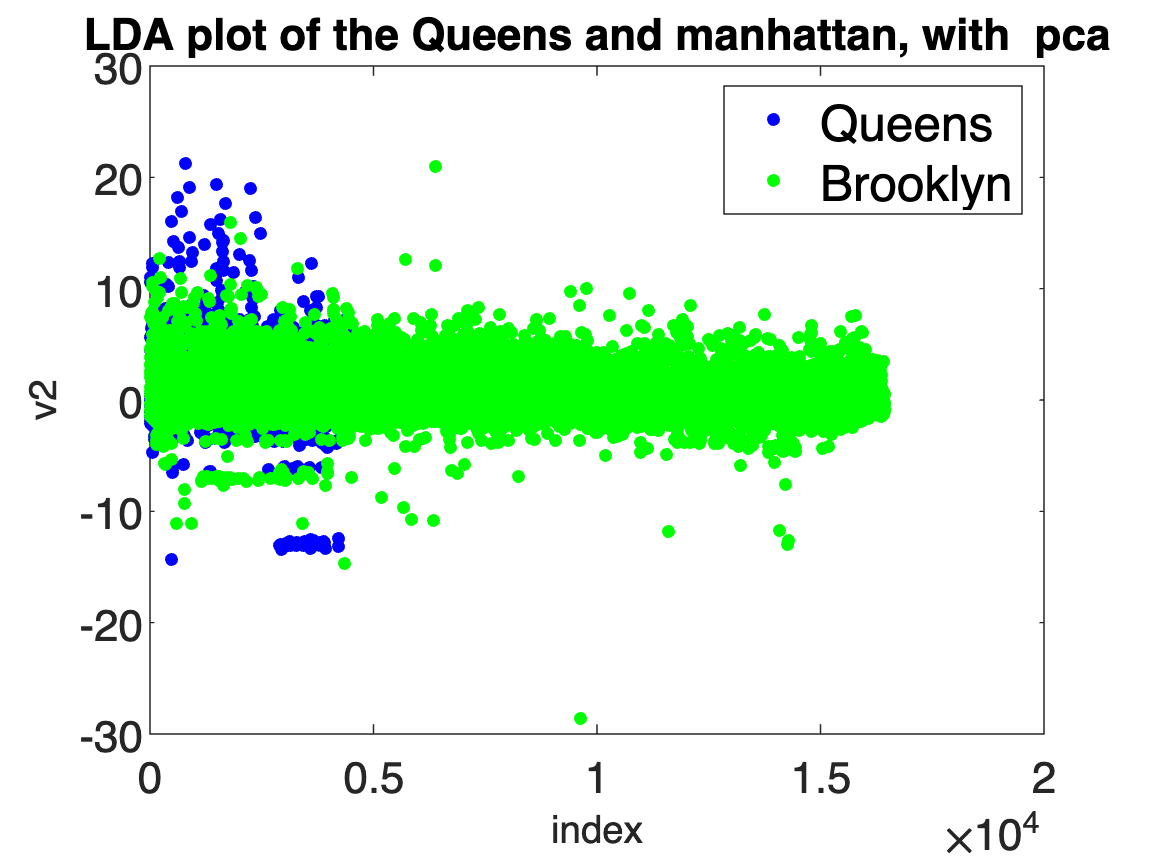

neighbourGroups = {'Queens', 'Brooklyn'};
filter = ismember(data.neighbourhood_group, neighbourGroups);
filteredData = data(filter, :);
% Extract the numerical variables from the filtered data into variable X
X1 = [filteredData.price, filteredData.minimum_nights, filteredData.number_of_reviews, ...
      filteredData.reviews_per_month, filteredData.calculated_host_listings_count, ...
      filteredData.availability_365];

norm_X1 = normalize(X1);
xbar = mean(norm_X1, 1);
Xtilda = norm_X1 - xbar;
s = svds(Xtilda, 200);


fracs = cumsum(s.^2)/norm(Xtilda,'fro')^2;
k = find(fracs > 0.80, 1, 'first');

% Perform singular value decomposition (SVD)
[U, S] = svds(Xtilda,k);
Yp = U .* diag(S)';
    

nei1 = 'Queens';
nei2 = 'Brooklyn';

X0 = Yp(strcmp(filteredData.neighbourhood_group, nei1), :);
X1 = Yp(strcmp(filteredData.neighbourhood_group, nei2), :);
Y1 = filteredData.neighbourhood_group(strcmp(filteredData.neighbourhood_group, nei1) | ...
                                     strcmp(filteredData.neighbourhood_group, nei2));

m0 = mean(X0, 1);
m1 = mean(X1, 1);
Sb = (m0 - m1).' * (m0 - m1);
Xtilde0 = X0 - m0;
Xtilde1 = X1 - m1;
Sw = Xtilde0.' * Xtilde0 + Xtilde1.' * Xtilde1;

[v1, lambda] = eigs(Sb, Sw);



Y = Yp*normalize(v1); %the projection

x0 = X0*normalize(v1);
x1 = X1*normalize(v1);
figure
hold on
plot(x0(:,1),'b.', 'markersize', 14)
plot(x1(:,1),'g.', 'markersize', 14)
set(gca, 'fontsize', 16)
title('LDA plot of the Queens and manhattan, with  pca', 'fontsize', 16)
xlabel('index', 'fontsize', 14)
ylabel('v2', 'fontsize', 14)
legend('Queens','Brooklyn','fontsize', 18)
box on

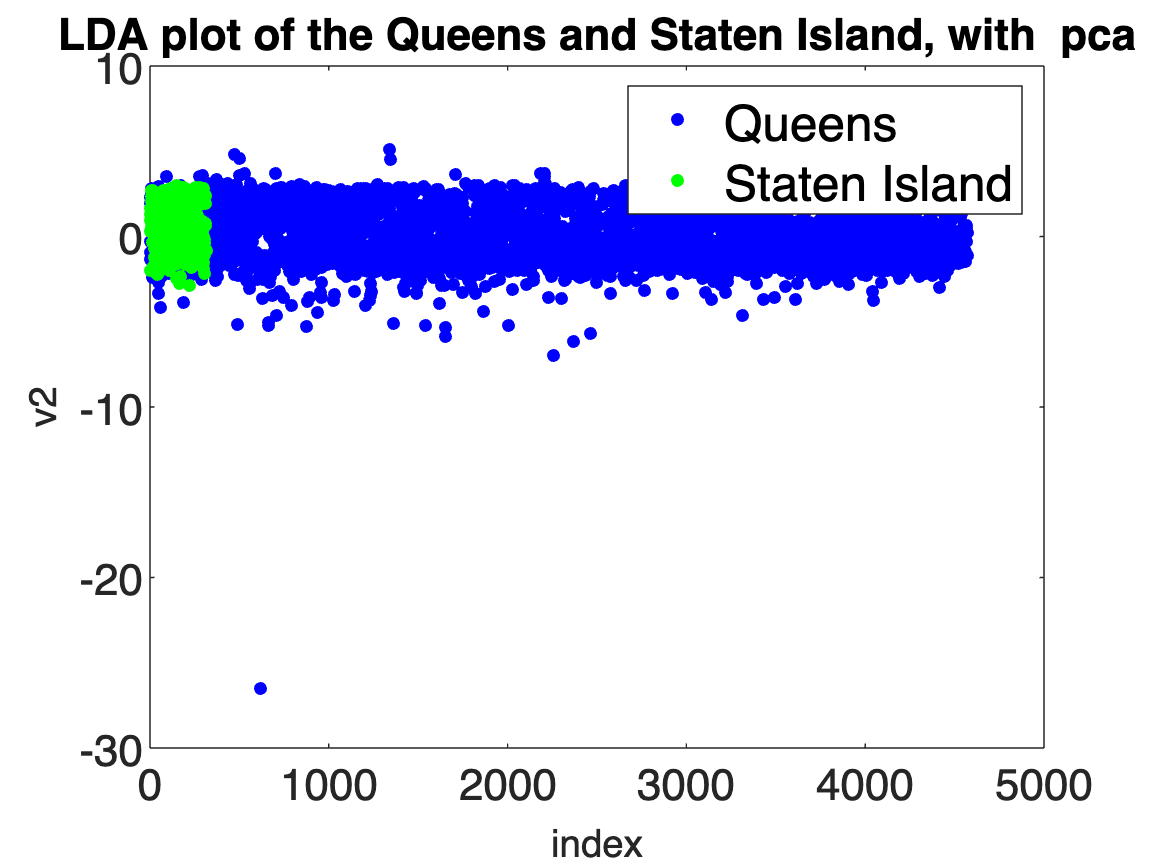


neighbourGroups = {'Queens', 'Staten Island'};
filter = ismember(data.neighbourhood_group, neighbourGroups);
filteredData = data(filter, :);
% Extract the numerical variables from the filtered data into variable X
X1 = [filteredData.price, filteredData.minimum_nights, filteredData.number_of_reviews, ...
      filteredData.reviews_per_month, filteredData.calculated_host_listings_count, ...
      filteredData.availability_365];

norm_X1 = normalize(X1);
xbar = mean(norm_X1, 1);
Xtilda = norm_X1 - xbar;
s = svds(Xtilda, 200);


fracs = cumsum(s.^2)/norm(Xtilda,'fro')^2;
k = find(fracs > 0.80, 1, 'first');

% Perform singular value decomposition (SVD)
[U, S] = svds(Xtilda,k);
Yp = U .* diag(S)';
    

place1 = 'Queens';
place2 = 'Staten Island';

X0 = Yp(strcmp(filteredData.neighbourhood_group, place1), :);
X1 = Yp(strcmp(filteredData.neighbourhood_group, place2), :);
Y1 = filteredData.neighbourhood_group(strcmp(filteredData.neighbourhood_group, place1) | ...
                                     strcmp(filteredData.neighbourhood_group, place2));

m0 = mean(X0, 1);
m1 = mean(X1, 1);
Sb = (m0 - m1).' * (m0 - m1);
Xtilde0 = X0 - m0;
Xtilde1 = X1 - m1;
Sw = Xtilde0.' * Xtilde0 + Xtilde1.' * Xtilde1;

[v1, lambda] = eigs(Sb, Sw);



Y = Yp*normalize(v1); %the projection

x0 = X0*normalize(v1);
x1 = X1*normalize(v1);
figure
hold on
plot(x0(:,1),'b.', 'markersize', 14)
plot(x1(:,1),'g.', 'markersize', 14)
set(gca, 'fontsize', 16)
title('LDA plot of the Queens and Staten Island, with  pca', 'fontsize', 16)
xlabel('index', 'fontsize', 14)
ylabel('v2', 'fontsize', 14)
legend('Queens ','Staten Island','fontsize', 18)
box on

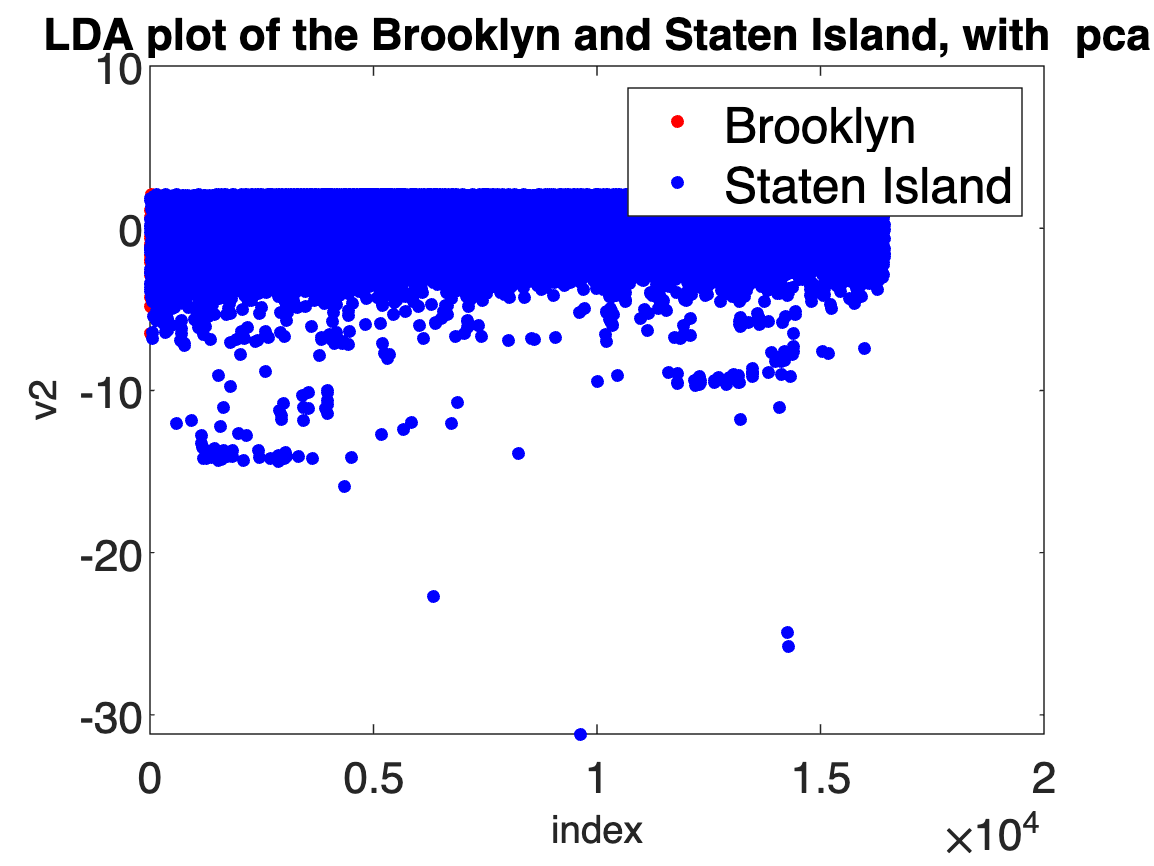

neighbourGroups = {'Staten Island', 'Brooklyn'};
filter = ismember(data.neighbourhood_group, neighbourGroups);
filteredData = data(filter, :);
% Extract the numerical variables from the filtered data into variable X
X1 = [filteredData.price, filteredData.minimum_nights, filteredData.number_of_reviews, ...
      filteredData.reviews_per_month, filteredData.calculated_host_listings_count, ...
      filteredData.availability_365];

norm_X1 = normalize(X1);
xbar = mean(norm_X1, 1);
Xtilda = norm_X1 - xbar;
s = svds(Xtilda, 200);


fracs = cumsum(s.^2)/norm(Xtilda,'fro')^2;
k = find(fracs > 0.80, 1, 'first');

% Perform singular value decomposition (SVD)
[U, S] = svds(Xtilda,k);
Yp = U .* diag(S)';
    

place1 = 'Staten Island';
place2 = 'Brooklyn';

X0 = Yp(strcmp(filteredData.neighbourhood_group, place1), :);
X1 = Yp(strcmp(filteredData.neighbourhood_group, place2), :);
Y1 = filteredData.neighbourhood_group(strcmp(filteredData.neighbourhood_group, place1) | ...
                                     strcmp(filteredData.neighbourhood_group, place2));

m0 = mean(X0, 1);
m1 = mean(X1, 1);
Sb = (m0 - m1).' * (m0 - m1);
Xtilde0 = X0 - m0;
Xtilde1 = X1 - m1;
Sw = Xtilde0.' * Xtilde0 + Xtilde1.' * Xtilde1;

[v1, lambda] = eigs(Sb, Sw);



Y = Yp*normalize(v1); %the projection

x0 = X0*normalize(v1);
x1 = X1*normalize(v1);
figure
hold on
plot(x0(:,1),'r.', 'markersize', 14)
plot(x1(:,1),'b.', 'markersize', 14)
set(gca, 'fontsize', 16)
title('LDA plot of the Brooklyn and Staten Island, with  pca', 'fontsize', 16)
xlabel('index', 'fontsize', 14)
ylabel('v2', 'fontsize', 14)
legend('Brooklyn','Staten Island','fontsize', 18)
box on

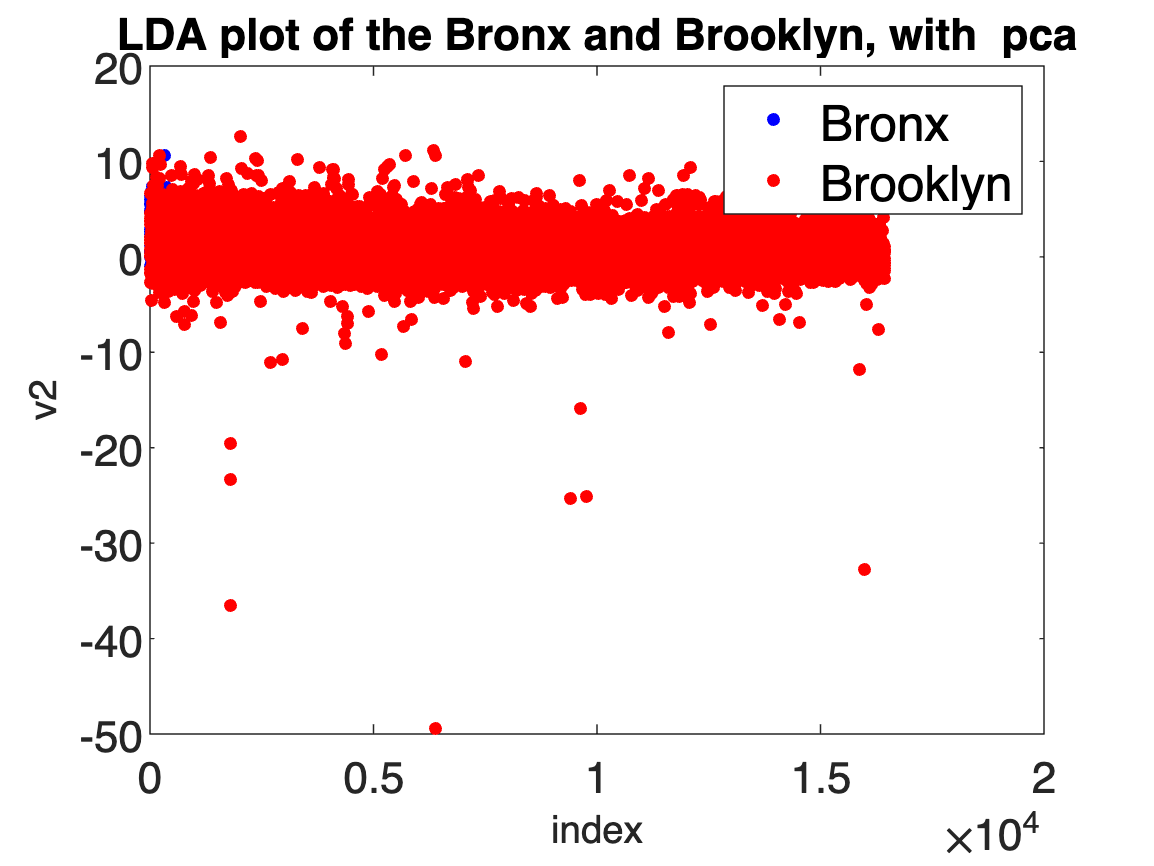

neighbourGroups = {'Bronx', 'Brooklyn'};
filter = ismember(data.neighbourhood_group, neighbourGroups);
filteredData = data(filter, :);
% Extract the numerical variables from the filtered data into variable X
X1 = [filteredData.price, filteredData.minimum_nights, filteredData.number_of_reviews, ...
      filteredData.reviews_per_month, filteredData.calculated_host_listings_count, ...
      filteredData.availability_365];

norm_X1 = normalize(X1);
xbar = mean(norm_X1, 1);
Xtilda = norm_X1 - xbar;
s = svds(Xtilda, 200);


fracs = cumsum(s.^2)/norm(Xtilda,'fro')^2;
k = find(fracs > 0.80, 1, 'first');

% Perform singular value decomposition (SVD)
[U, S] = svds(Xtilda,k);
Yp = U .* diag(S)';
    

place1 = 'Bronx';
place2 = 'Brooklyn';

X0 = Yp(strcmp(filteredData.neighbourhood_group, place1), :);
X1 = Yp(strcmp(filteredData.neighbourhood_group, place2), :);
Y1 = filteredData.neighbourhood_group(strcmp(filteredData.neighbourhood_group, place1) | ...
                                     strcmp(filteredData.neighbourhood_group, place2));

m0 = mean(X0, 1);
m1 = mean(X1, 1);
Sb = (m0 - m1).' * (m0 - m1);
Xtilde0 = X0 - m0;
Xtilde1 = X1 - m1;
Sw = Xtilde0.' * Xtilde0 + Xtilde1.' * Xtilde1;

[v1, lambda] = eigs(Sb, Sw);



Y = Yp*normalize(v1); %the projection

x0 = X0*normalize(v1);
x1 = X1*normalize(v1);
figure
hold on
plot(x0(:,1),'b.', 'markersize', 14)
plot(x1(:,1),'r.', 'markersize', 14)
set(gca, 'fontsize', 16)
title('LDA plot of the Bronx and Brooklyn, with  pca', 'fontsize', 16)
xlabel('index', 'fontsize', 14)
ylabel('v2', 'fontsize', 14)
legend('Bronx','Brooklyn','fontsize', 18)
box on

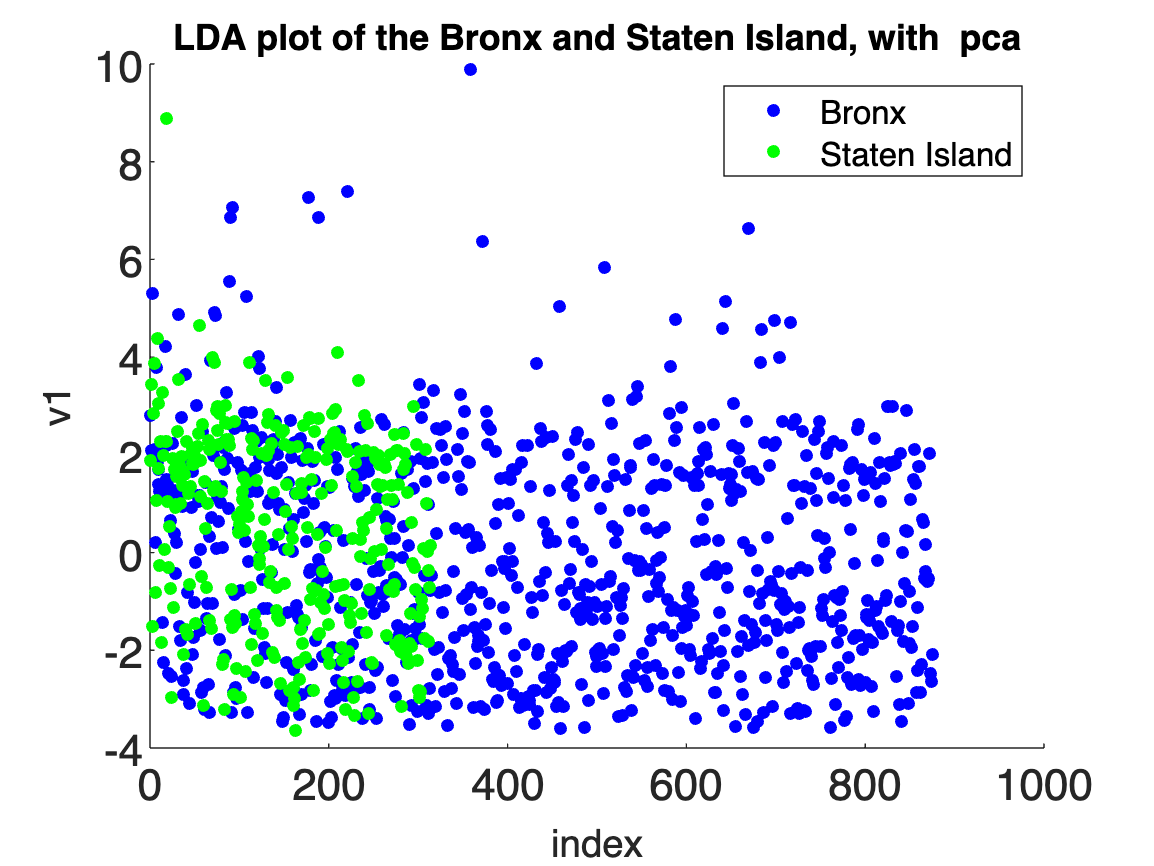

  neighbourGroups = {'Bronx', 'Staten Island'};
filter = ismember(data.neighbourhood_group, neighbourGroups);
filteredData = data(filter, :);
% Extract the numerical variables from the filtered data into variable X
X1 = [filteredData.price, filteredData.minimum_nights, filteredData.number_of_reviews, ...
      filteredData.reviews_per_month, filteredData.calculated_host_listings_count, ...
      filteredData.availability_365];
norm_X1 = normalize(X1);
xbar = mean(norm_X1, 1);
Xtilda = norm_X1 - xbar;
s = svds(Xtilda, 200);


fracs = cumsum(s.^2)/norm(Xtilda,'fro')^2;
k = find(fracs > 0.80, 1, 'first');

% Perform singular value decomposition (SVD)
[U, S] = svds(Xtilda,k);
Yp = U .* diag(S)';
    

place1 = 'Bronx';
place2 = 'Staten Island';

X0 = Yp(strcmp(filteredData.neighbourhood_group, place1), :);
X1 = Yp(strcmp(filteredData.neighbourhood_group, place2), :);
Y1 = filteredData.neighbourhood_group(strcmp(filteredData.neighbourhood_group, place1) | ...
                                     strcmp(filteredData.neighbourhood_group, place2));

m0 = mean(X0, 1);
m1 = mean(X1, 1);
Sb = (m0 - m1).' * (m0 - m1);
Xtilde0 = X0 - m0;
Xtilde1 = X1 - m1;
Sw = Xtilde0.' * Xtilde0 + Xtilde1.' * Xtilde1;

[v1, lambda] = eigs(Sb, Sw);



Y = Yp*normalize(v1); %the projection

x0 = X0*normalize(v1);
x1 = X1*normalize(v1);
figure
hold on
plot(x0(:,1),'b.', 'markersize', 14)
plot(x1(:,1),'g.', 'markersize', 14)
set(gca, 'fontsize', 16)
title('LDA plot of the Bronx and Staten Island, with  pca', 'fontsize', 13)
xlabel('index', 'fontsize', 14)
ylabel('v1', 'fontsize', 14)
legend('Bronx','Staten Island','fontsize', 12) 

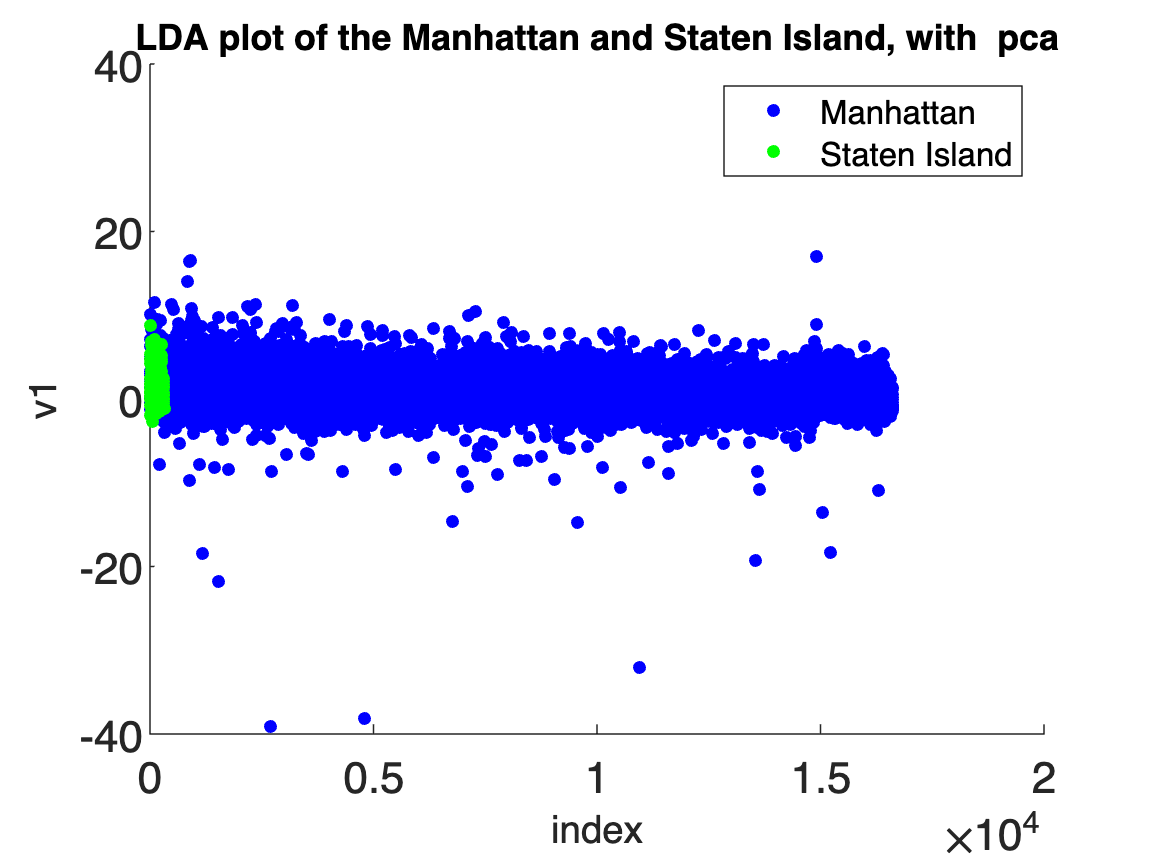




neighbourGroups = {'Manhattan', 'Staten Island'};
filter = ismember(data.neighbourhood_group, neighbourGroups);
filteredData = data(filter, :);
% Extract the numerical variables from the filtered data into variable X
X1 = [filteredData.price, filteredData.minimum_nights, filteredData.number_of_reviews, ...
      filteredData.reviews_per_month, filteredData.calculated_host_listings_count, ...
      filteredData.availability_365];
norm_X1 = normalize(X1);
xbar = mean(norm_X1, 1);
Xtilda = norm_X1 - xbar;
s = svds(Xtilda, 200);


fracs = cumsum(s.^2)/norm(Xtilda,'fro')^2;
k = find(fracs > 0.80, 1, 'first');

% Perform singular value decomposition (SVD)
[U, S] = svds(Xtilda,k);
Yp = U .* diag(S)';
    

place1 = 'Manhattan';
place2 = 'Staten Island';

X0 = Yp(strcmp(filteredData.neighbourhood_group, place1), :);
X1 = Yp(strcmp(filteredData.neighbourhood_group, place2), :);
Y1 = filteredData.neighbourhood_group(strcmp(filteredData.neighbourhood_group, place1) | ...
                                     strcmp(filteredData.neighbourhood_group, place2));

m0 = mean(X0, 1);
m1 = mean(X1, 1);
Sb = (m0 - m1).' * (m0 - m1);
Xtilde0 = X0 - m0;
Xtilde1 = X1 - m1;
Sw = Xtilde0.' * Xtilde0 + Xtilde1.' * Xtilde1;

[v1, lambda] = eigs(Sb, Sw);



Y = Yp*normalize(v1); %the projection

x0 = X0*normalize(v1);
x1 = X1*normalize(v1);
figure
hold on
plot(x0(:,1),'b.', 'markersize', 14)
plot(x1(:,1),'g.', 'markersize', 14)
set(gca, 'fontsize', 16)
title('LDA plot of the Manhattan and Staten Island, with  pca', 'fontsize', 13)
xlabel('index', 'fontsize', 14)
ylabel('v1', 'fontsize', 14)
legend('Manhattan','Staten Island','fontsize', 12)

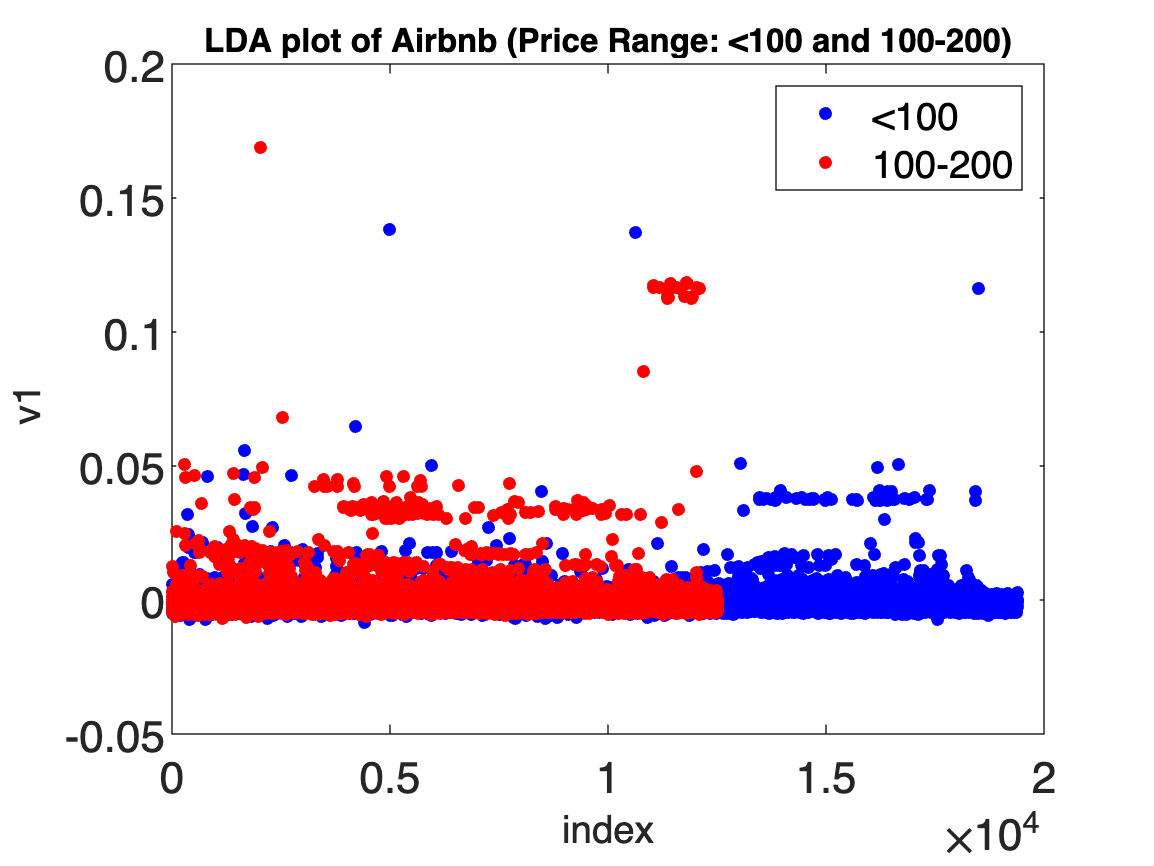




data = readtable('AB_NYC_2019.csv');

abodata = rmmissing(data);
filtered_data = abodata(abodata.price < 200, :);

X = [filtered_data.minimum_nights, filtered_data.number_of_reviews, filtered_data.reviews_per_month, filtered_data.calculated_host_listings_count, filtered_data.availability_365];
norm_X = normalize(X);
xbar = mean(norm_X, 1);
Xtilda = norm_X - xbar;
s = svds(Xtilda, 200);

fracs = cumsum(s.^2) / norm(Xtilda, 'fro')^2;
k = find(fracs > 0.80, 1, 'first');

% Perform singular value decomposition (SVD)
[U, S] = svds(Xtilda, k);
Yp = U .* diag(S)';

% Get the price ranges for the filtered data
price_edges = [0, 100, 200];
price_labels = {'<100', '100-200'};
price_ranges = discretize(filtered_data.price, price_edges, price_labels, 'IncludedEdge', 'right');

% Filter the data for the desired price ranges
X0 = Yp(strcmp(price_ranges, '<100'), :);
X1 = Yp(strcmp(price_ranges, '100-200'), :);

% Perform LDA between the filtered data
m0 = mean(X0, 1);
m1 = mean(X1, 1);
Sb = (m0 - m1).' * (m0 - m1);
Xtilde0 = X0 - m0;
Xtilde1 = X1 - m1;
Sw = Xtilde0.' * Xtilde0 + Xtilde1.' * Xtilde1;

[v1, lambda] = eigs(Sb, Sw);

% Project the data onto the LDA space
Y = Yp * v1;

x0 = X0 * v1;
x1 = X1 * v1;

figure;
hold on;
plot(x0(:, 1), 'b.', 'markersize', 14);
plot(x1(:, 1), 'r.', 'markersize', 14);
set(gca, 'fontsize', 16);
title('LDA plot of Airbnb (Price Range: <100 and 100-200)', 'fontsize', 12);
xlabel('index', 'fontsize', 14);
ylabel('v1 ', 'fontsize', 14);
legend('<100', '100-200', 'fontsize', 14);
box on;

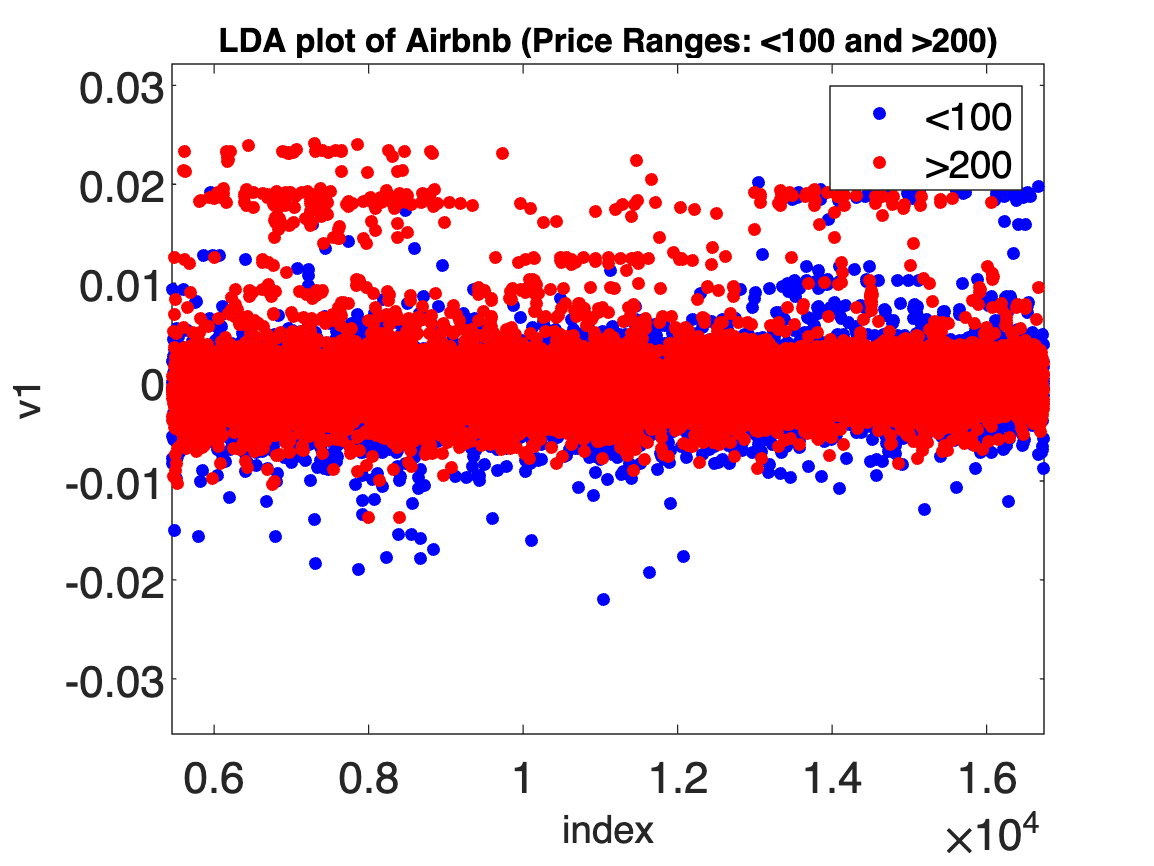


%









data = readtable('AB_NYC_2019.csv');

abodata = rmmissing(data);
filtered_data = abodata;

X = [filtered_data.minimum_nights, filtered_data.number_of_reviews, filtered_data.reviews_per_month, filtered_data.calculated_host_listings_count, filtered_data.availability_365];
norm_X = normalize(X);
xbar = mean(norm_X, 1);
Xtilda = norm_X - xbar;
s = svds(Xtilda, 200);

fracs = cumsum(s.^2) / norm(Xtilda, 'fro')^2;
k = find(fracs > 0.80, 1, 'first');

% Perform singular value decomposition (SVD)
[U, S] = svds(Xtilda, k);
Yp = U .* diag(S)';

% Get the price ranges for the filtered data
price_ranges = discretize(filtered_data.price, [0, 100, Inf], {'<100', '>200'}, 'IncludedEdge', 'right');

% Filter the data for the desired price ranges
X0 = Yp(strcmp(price_ranges, '<100'), :);
X2 = Yp(strcmp(price_ranges, '>200'), :);

% Perform LDA between the filtered data
m0 = mean(X0, 1);
m2 = mean(X2, 1);
Sb = (m0 - m2).' * (m0 - m2);
Xtilde0 = X0 - m0;
Xtilde2 = X2 - m2;
Sw = Xtilde0.' * Xtilde0 + Xtilde2.' * Xtilde2;

[v1, lambda] = eigs(Sb, Sw);

% Project the data onto the LDA space
Y = Yp * v1;

x0 = X0 * v1;
x2 = X2 * v1;

figure;
hold on;
plot(x0(:, 1), 'b.', 'markersize', 14);
plot(x2(:, 1), 'r.', 'markersize', 14);
set(gca, 'fontsize', 16);
title('LDA plot of Airbnb (Price Ranges: <100 and >200)', 'fontsize', 12);
xlabel('index', 'fontsize', 14);
ylabel('v1', 'fontsize', 14);
legend('<100', '>200', 'fontsize', 14);
box on;

MULTIDIMENSIONAL SCALING

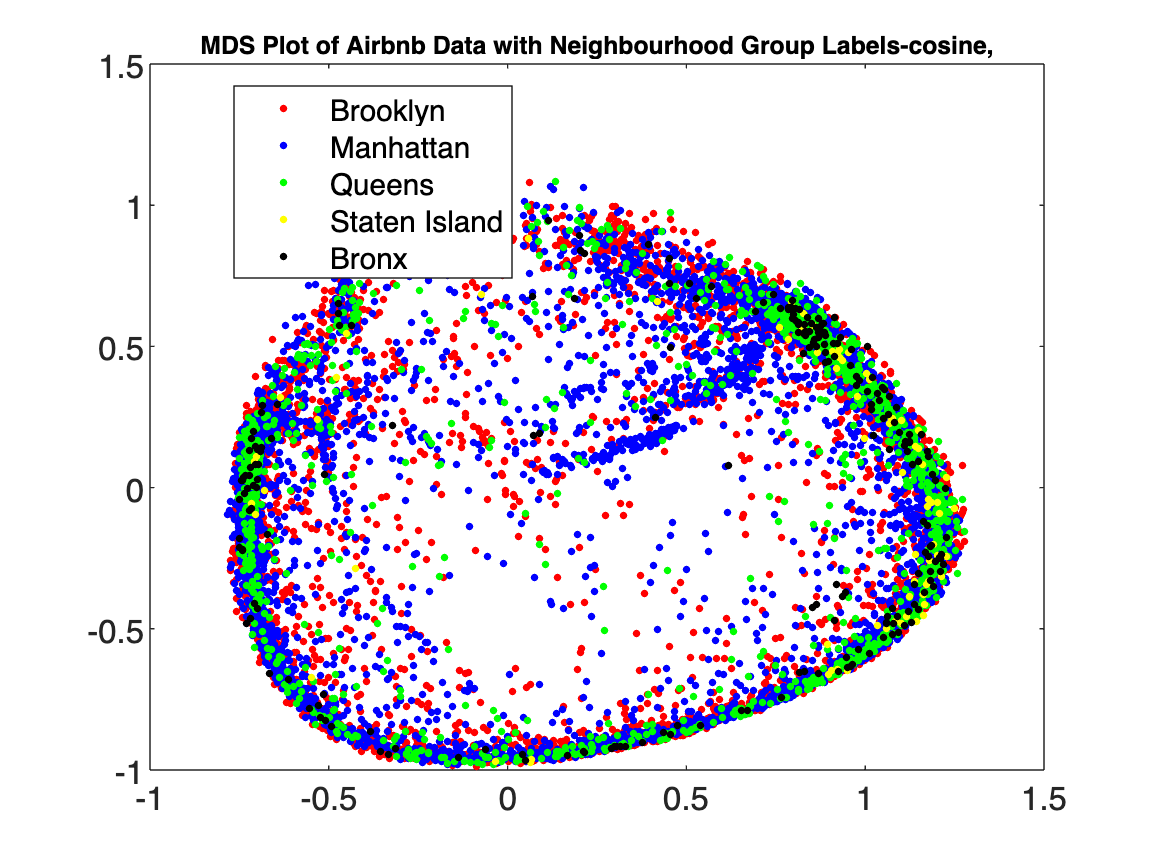


data = readtable('AB_NYC_2019.csv');

abodata = rmmissing(data(1:20000,:));
filtered_data = abodata;

X = [filtered_data.minimum_nights, filtered_data.number_of_reviews, filtered_data.calculated_host_listings_count, filtered_data.availability_365];
norm_X = normalize(X);
D_mat = pdist(norm_X,'cosine');

% Convert to square matrix
D_mat = squareform(D_mat);

% Get projection coordinates
[Y,e] = cmdscale(D_mat, 2);

% Plot MDS with neighbourhood group labels
figure;
gscatter(Y(:, 1), Y(:, 2), filtered_data.neighbourhood_group, 'rbgyk', '.....', 8);
set(gca, 'fontsize', 12);

title('MDS Plot of Airbnb Data with Neighbourhood Group Labels-cosine,', 'fontsize', 9);
legend('Location', 'best');

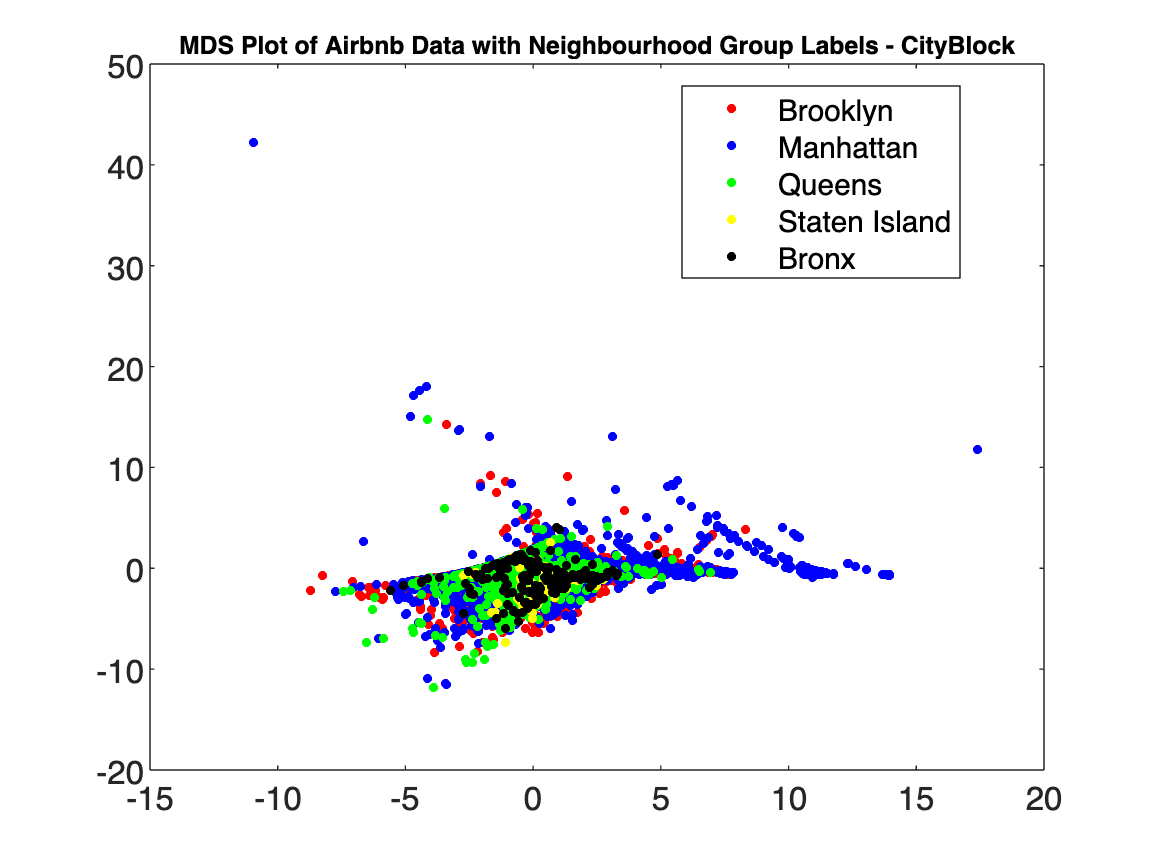

data = readtable('AB_NYC_2019.csv');

abodata = rmmissing(data(1:20000,:));
filtered_data = abodata;

X = [filtered_data.minimum_nights, filtered_data.number_of_reviews, filtered_data.calculated_host_listings_count, filtered_data.availability_365];
norm_X = normalize(X);
D_mat = pdist(norm_X,'cityblock');

% Convert to square matrix
D_mat = squareform(D_mat);

% Get projection coordinates
[Y,e] = cmdscale(D_mat, 2);

% Plot MDS with neighbourhood group labels
figure;
gscatter(Y(:, 1), Y(:, 2), filtered_data.neighbourhood_group, 'rbgyk', '.....', 10);
set(gca, 'fontsize', 12);

title('MDS Plot of Airbnb Data with Neighbourhood Group Labels - CityBlock', 'fontsize', 9);
legend('Location', 'best');

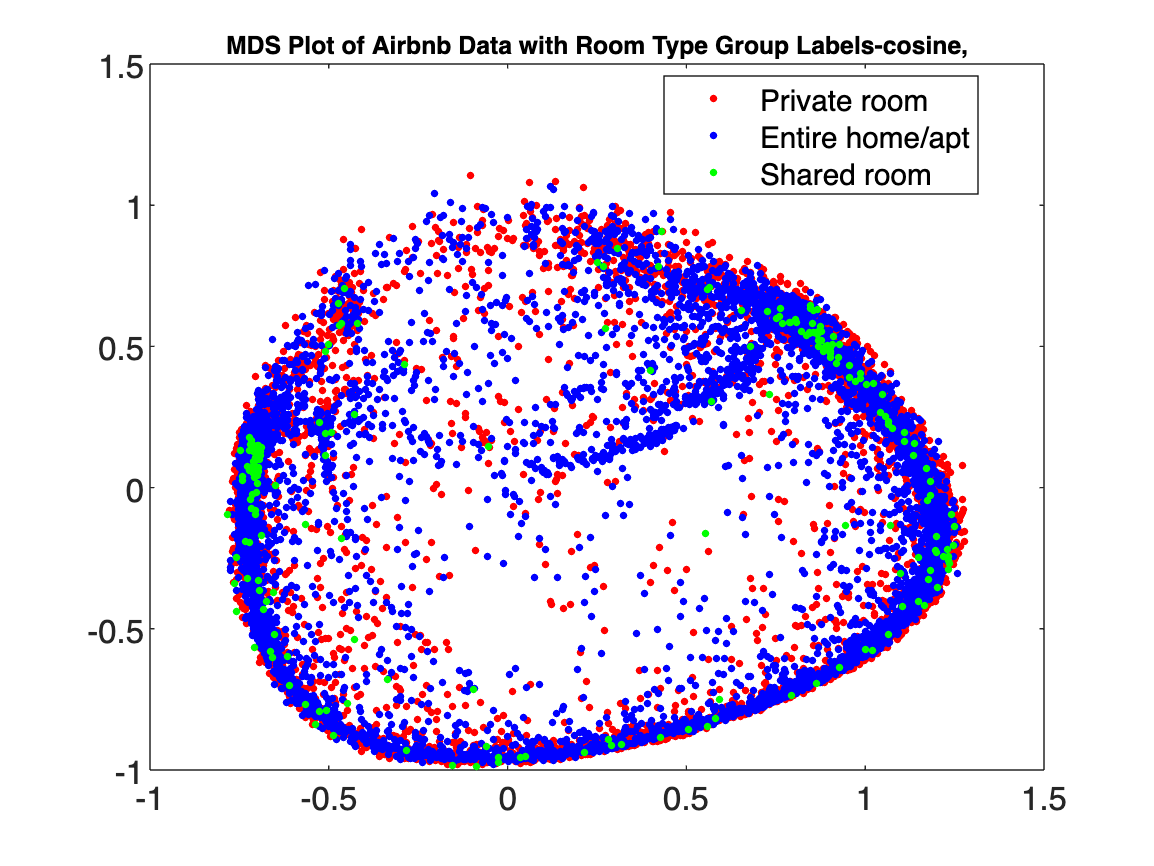

data = readtable('AB_NYC_2019.csv');

abodata = rmmissing(data(1:20000,:));
filtered_data = abodata;

X = [filtered_data.minimum_nights, filtered_data.number_of_reviews, filtered_data.calculated_host_listings_count, filtered_data.availability_365];
norm_X = normalize(X);
D_mat = pdist(norm_X,'cosine');

% Convert to square matrix
D_mat = squareform(D_mat);

% Get projection coordinates
[Y,e] = cmdscale(D_mat, 2);

% Plot MDS with neighbourhood group labels
figure;
gscatter(Y(:, 1), Y(:, 2), filtered_data.room_type, 'rbg', '...', 8);
set(gca, 'fontsize', 12);

title('MDS Plot of Airbnb Data with Room Type Group Labels-cosine,', 'fontsize', 9);
legend('Location', 'best');

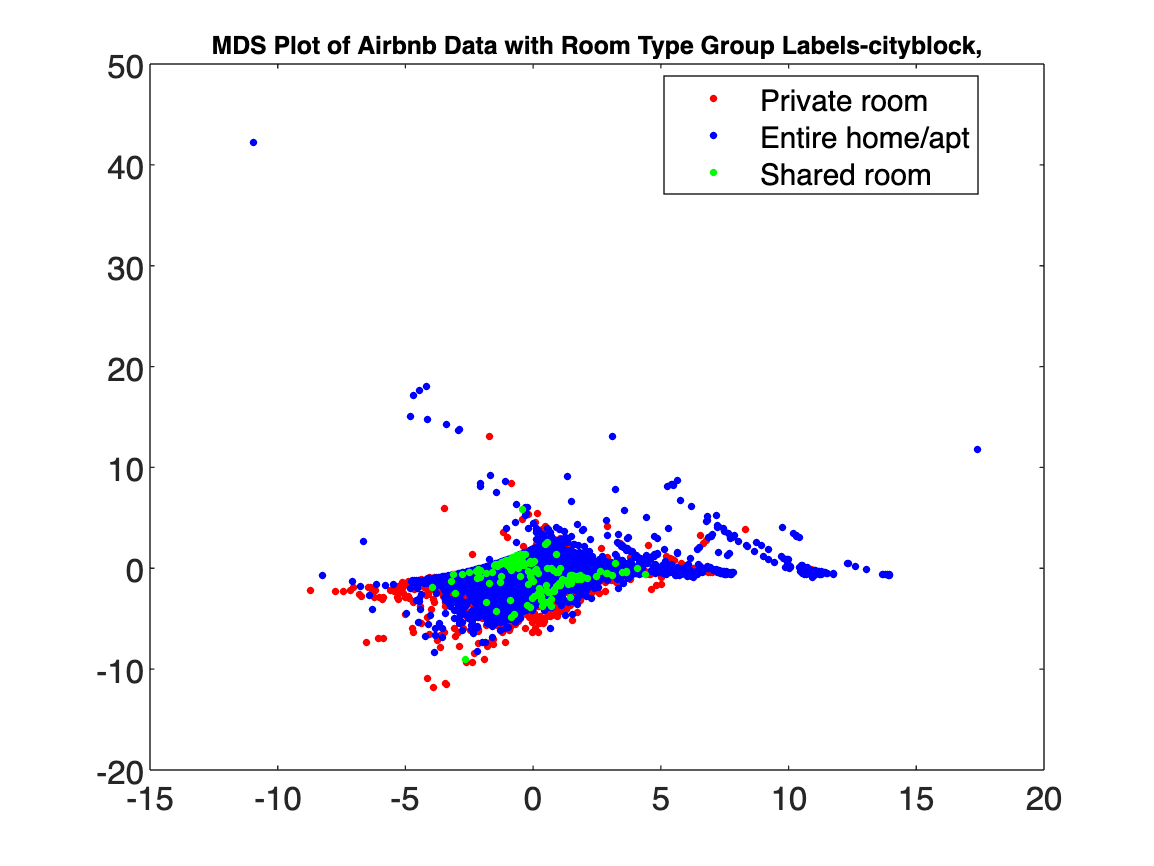



data = readtable('AB_NYC_2019.csv');

abodata = rmmissing(data(1:20000,:));
filtered_data = abodata;

X = [filtered_data.minimum_nights, filtered_data.number_of_reviews, filtered_data.calculated_host_listings_count, filtered_data.availability_365];
norm_X = normalize(X);
D_mat = pdist(norm_X,'cityblock');

% Convert to square matrix
D_mat = squareform(D_mat);

% Get projection coordinates
[Y,e] = cmdscale(D_mat, 2);

% Plot MDS with neighbourhood group labels
figure;
gscatter(Y(:, 1), Y(:, 2), filtered_data.room_type, 'rbg', '...', 8);
set(gca, 'fontsize', 12);

title('MDS Plot of Airbnb Data with Room Type Group Labels-cityblock,', 'fontsize', 9);
legend('Location', 'best');

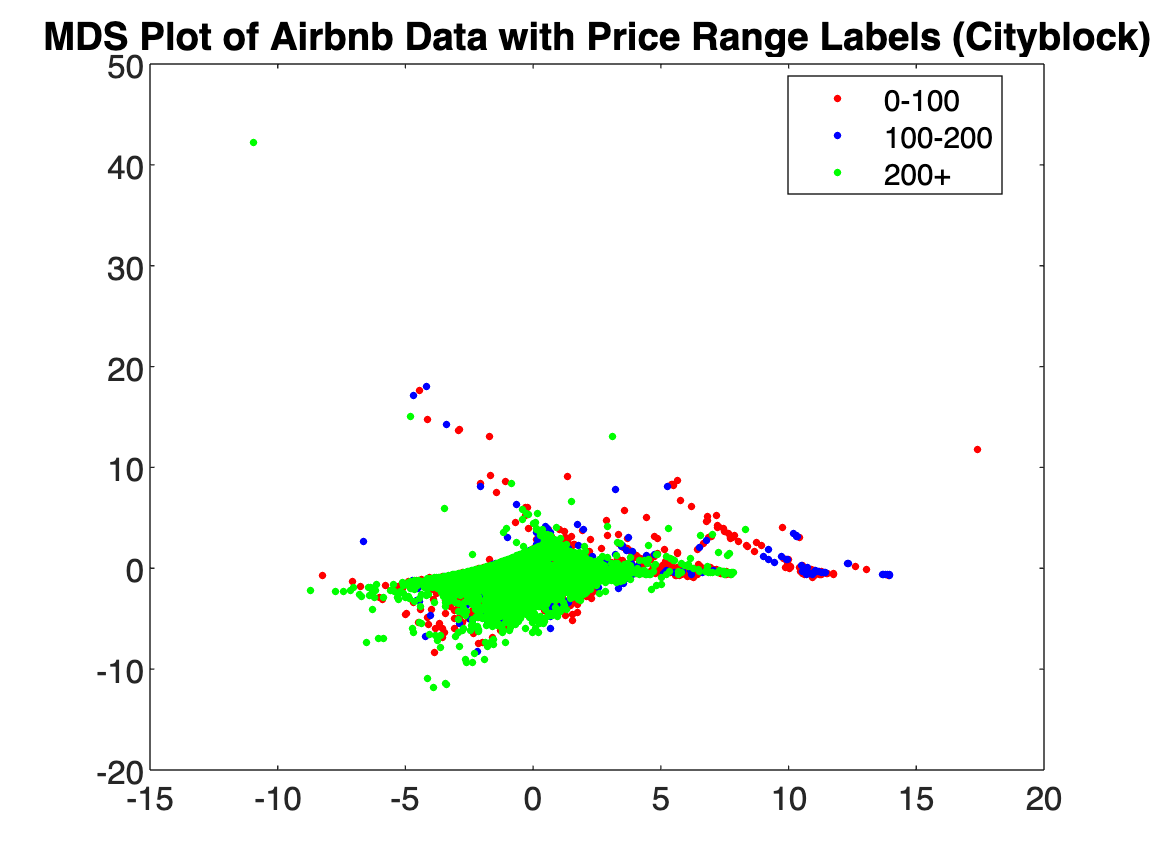

clear
data = readtable('AB_NYC_2019.csv');

abodata = rmmissing(data(1:20000, :));
filtered_data = abodata;

X = [filtered_data.minimum_nights, filtered_data.number_of_reviews, filtered_data.calculated_host_listings_count, filtered_data.availability_365];
norm_X = normalize(X);
D_mat = pdist(norm_X, 'cityblock');

% Convert to square matrix
D_mat = squareform(D_mat);

% Get projection coordinates
[Y, e] = cmdscale(D_mat, 2);

% Get price ranges for filtering
price_edges = [0, 100, 200, inf];
price_labels = {'0-100', '100-200', '200+'};
price_ranges = discretize(filtered_data.price, price_edges, price_labels, 'IncludedEdge', 'right');

% Plot MDS with price range labels
figure;
gscatter(Y(:, 1), Y(:, 2), price_ranges, 'rbg', '...', 8);
set(gca, 'fontsize', 12);

title('MDS Plot of Airbnb Data with Price Range Labels (Cityblock)', 'fontsize', 14);

legend(price_labels, 'Location', 'best');
box on;

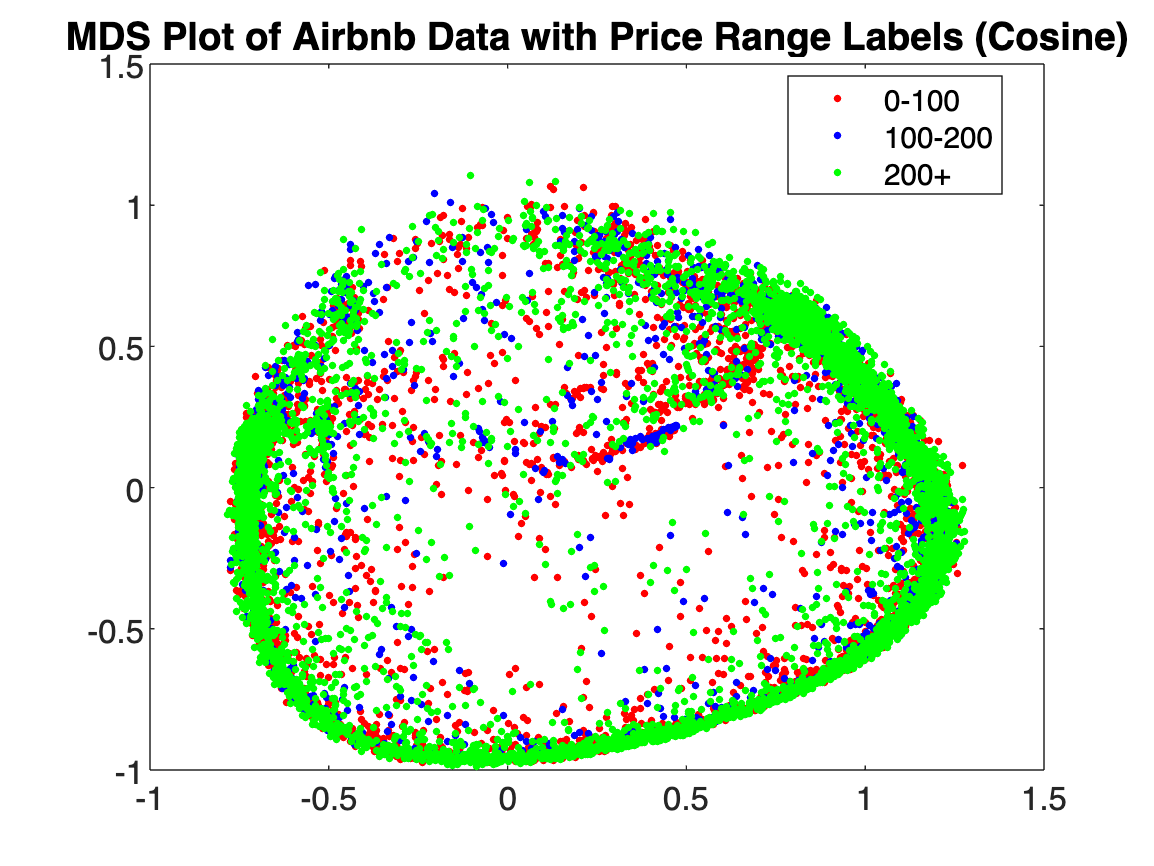

data = readtable('AB_NYC_2019.csv');

abodata = rmmissing(data(1:20000, :));
filtered_data = abodata;

X = [filtered_data.minimum_nights, filtered_data.number_of_reviews, filtered_data.calculated_host_listings_count, filtered_data.availability_365];
norm_X = normalize(X);
D_mat = pdist(norm_X, 'cosine');

% Convert to square matrix
D_mat = squareform(D_mat);

% Get projection coordinates
[Y, e] = cmdscale(D_mat, 2);

% Get price ranges for filtering
price_edges = [0, 100, 200, inf];
price_labels = {'0-100', '100-200', '200+'};
price_ranges = discretize(filtered_data.price, price_edges, price_labels, 'IncludedEdge', 'right');

% Plot MDS with price range labels
figure;
gscatter(Y(:, 1), Y(:, 2), price_ranges, 'rbg', '...', 8);
set(gca, 'fontsize', 12);

title('MDS Plot of Airbnb Data with Price Range Labels (Cosine)', 'fontsize', 14);

legend(price_labels, 'Location', 'best');
box on;